# Lab 7-8

For this lab, I chose the high pt signal (pt = 1000-1200). In this lab I will be exploring different variables in the Higgs and QCD data set.

**Section 1**

In this section, I am looking to the mass variable of the Higgs and QCD data set. I first import the data and store the Higgs data and QCD data into two different matrices.

clear all
close all
clc

h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');


After I import the data, I plotted the mass of both Higgs data and QCD data. I stacked two histograms together and see what do the distribution look like. 

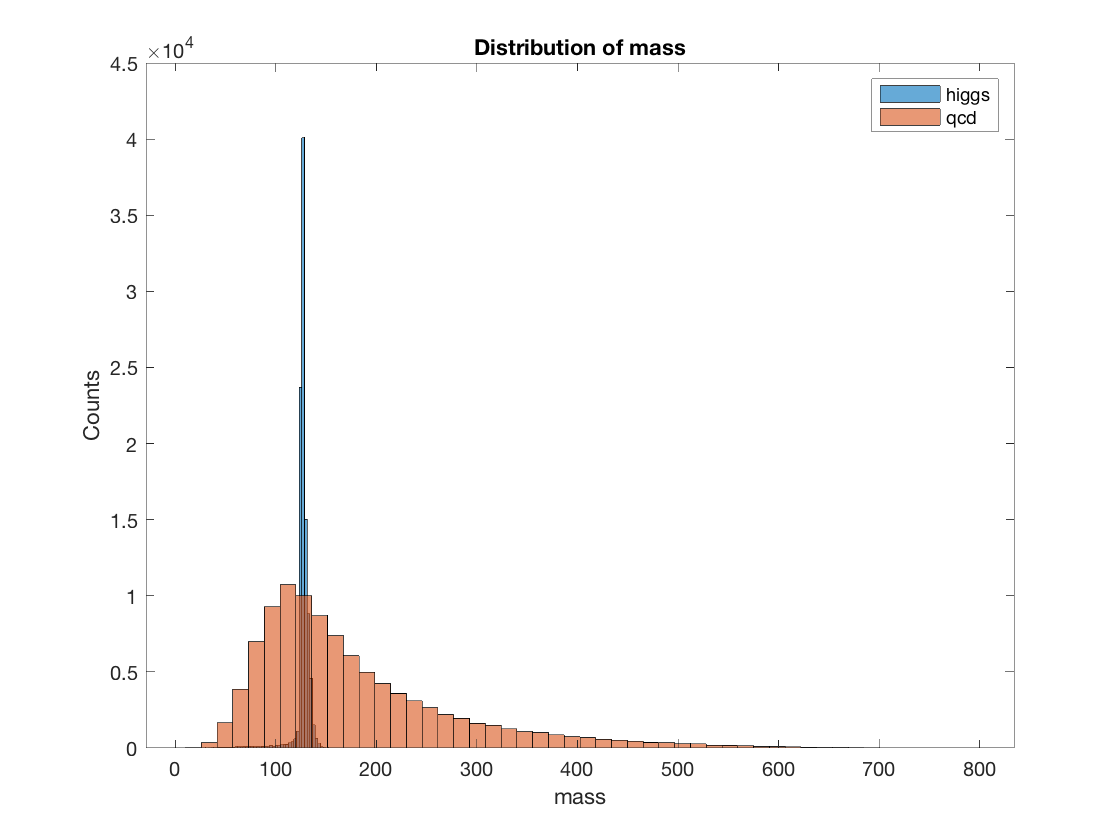

%plotmass of higgs and qcd data
mass_higgs = higgs(4,:);
mass_qcd = qcd(4,:);

histogram(higgs(4,:),50)
hold on
histogram(qcd(4,:),50)
legend('higgs','qcd')
title('Distribution of mass')
ylabel('Counts')
xlabel('mass')
hold off

The distribution of the Higgs and QCD data looks like a Poisson. However, Poisson distribution is not a good enough fit for those two data. Therefore, I am going to turn the counts of data into probability. By doing so, we don't need to worry about fitting the distribution with a particular distribution. We can just integrate the probability distribution that was converted from the original data distribution by doing Reiman sum.

The following code convert the original data distribution into probability distribution. The probability was found by doing the math:


$$\begin{array}{l}
P_{\mathrm{m1}} =\frac{N_{\mathrm{m1}} }{N_{\mathrm{tot}} },\mathrm{Where}\;P_{\mathrm{m1}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{probability}\;\mathrm{of}\;\mathrm{measuring}\;\mathrm{mass}\;\mathrm{to}\;\mathrm{be}\;m_1 ,\\
N_{\mathrm{m1}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{number}\;\mathrm{of}\;\mathrm{particles}\;\mathrm{with}\;\mathrm{mass}\;m_1 \\
N_{\mathrm{tot}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{number}\;\mathrm{of}\;\mathrm{total}\;\mathrm{particles}
\end{array}$$


binranges_qcd = linspace(0,800,1000);
binranges_higgs = linspace(min(mass_higgs),max(mass_higgs),1000);
pd_qcd = histc(mass_qcd,binranges_qcd)/100000;
pd_higgs = histc(mass_higgs,binranges_higgs)/100000;

N_higgs = 50;
N_qcd = 2000;
N_r = N_higgs/sqrt(N_qcd);

N_higgs = 50 and N_qcd = 2000. And N_higgs/sqrt(N_qcd) = 1.118. This value is very close to 1, which means $N_{\mathrm{Higgs}} \approx \sqrt{N_{\mathrm{qcd}} }$

In the later part we are going to cut away some data and see if the ratio N_higgs/sqrt(N_qcd) could be improved.

**Section 2**

In this section I am going to cut some data from the QCD mass data to optimize the significance of our signal. I will try various different ways to cut the data.

When we are optimizing the significance of the signal, we are basically maximize the ratio: $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$. The ratio of numbers of Higgs data to the square root of QCD data. We want to cut our data in ta way that this ratio if optimized because it means that we included most of the Higgs data while throwing away most of the QCD data, the background. 

$N_{\textrm{Higgs}} \;\textrm{and}\;N_{\textrm{qcd}} \;\textrm{are}\;\textrm{calculated}\;\textrm{as}\;\textrm{follow}$:


$$\begin{array}{l}
N_{\mathrm{Higgs}} =50*\int_{125-x}^{125+x} P_{\mathrm{Higgs}} \left(x\right)\mathrm{dx}\\
N_{\mathrm{qcd}} =2000*\int_{125-x}^{125+x} P_{\mathrm{qcd}} \left(x\right)\mathrm{dx}
\end{array}$$


Since we know that Higgs data has a distribution center around 125, I will cut the data that is some distance away from 125 and cut the QCD data in the same way. The ratio of $N_{\textrm{Higgs}} \;\textrm{and}\;N_{\textrm{qcd}}$ before cutting is 50 to 2000. For every 2000 QCD data, there are 50 Higgs. When we calculate the ratio after cutting, we calculate the probability of Higgs data being inside the section of the data that we keep and multiply the probability with 50 to find out how many of the 50 Higgs data points were kept. Then we calculate the probability of the QCD data being inside the section of data that we keep and multiple the probability by 2000. These two steps will give us $N_{\textrm{Higgs}} \;\textrm{and}\;N_{\textrm{qcd}}$. After calculating $N_{\textrm{Higgs}} \;\textrm{and}\;N_{\textrm{qcd}}$ we can take the ratio. 

Note: The section of the data we keep is: signal value = [125-x,125+x]. Where x is the parameter that we manipulate to optimize the ratio of $N_{\textrm{Higgs}} \;\textrm{to}\;N_{\textrm{qcd}}$.

The code below use iterative method to find the parameter x that optimize the ratio. 

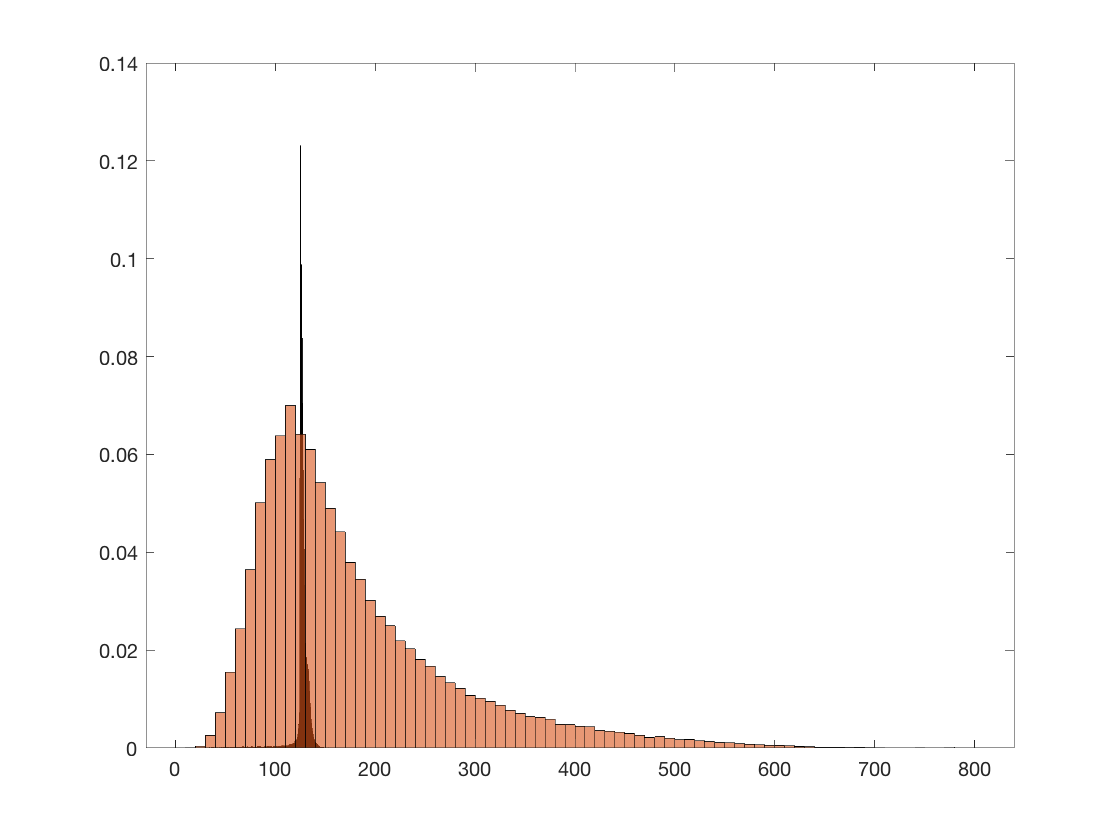

histogram(mass_higgs,'Normalization','probability')
hold on
histogram(mass_qcd,'Normalization','probability')
hold off


cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    

    
    i_higgs_r = binranges_higgs>=mean(mass_higgs)+cut(i);
    i_higgs_l = binranges_higgs<=mean(mass_higgs)-cut(i);
    i_qcd_r = binranges_qcd>=mean(mass_higgs)+cut(i);
    i_qcd_l = binranges_qcd<=mean(mass_higgs)-cut(i);
    
    P_higgs = 1-sum(pd_higgs(i_higgs_l))-sum(pd_higgs(i_higgs_r));
    P_qcd = 1-sum(pd_qcd(i_qcd_l))-sum(pd_qcd(i_qcd_r));
    

   
    ratio(i) = 50*P_higgs/sqrt(2000*P_qcd);
end
cut_opti = cut(ratio==max(ratio));

In the end, x is found to be 2, Which means we throw away the data that has a signal value smaller than 125-2 or greater than 125+2 in both QCD data and Higgs data. When we cut the data this way, the ratio : $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$ is optimized.

The optimized ratio is 4.5317 in the end. It shows that the significance has been improved because the ratio was about 1.18 before the cuts.

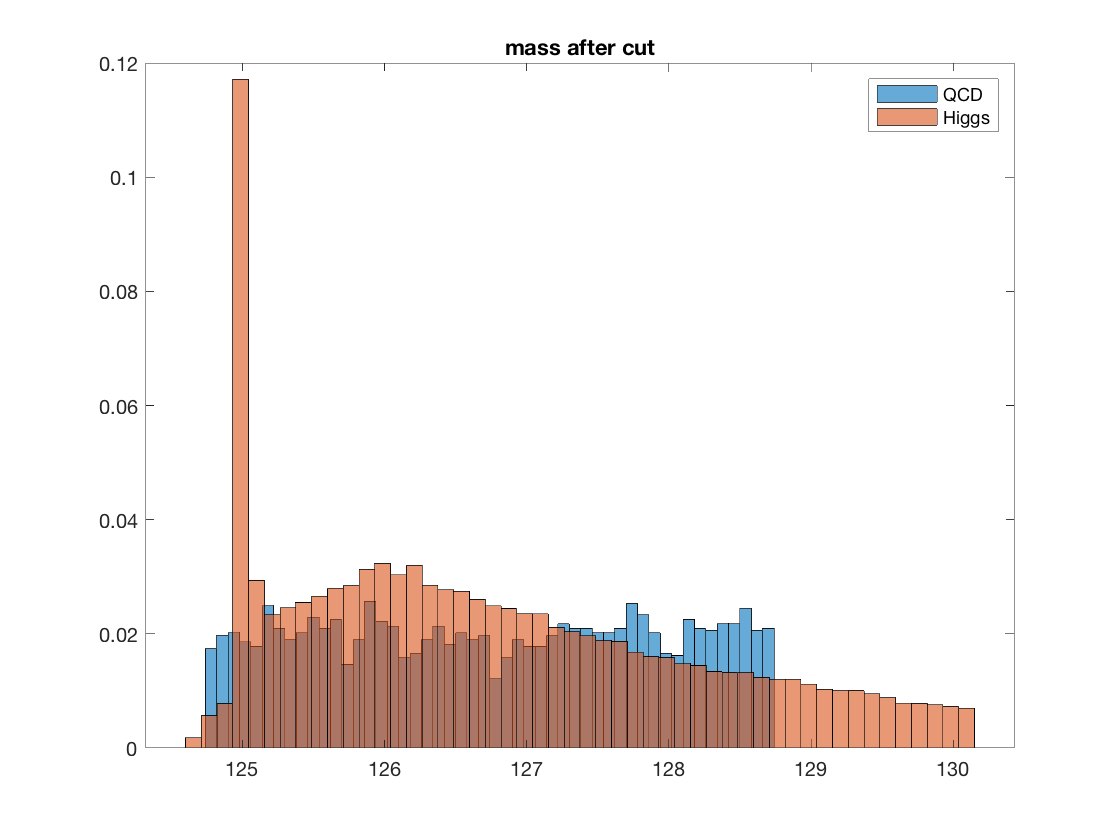

mass_higgs(mass_higgs<mean(mass_higgs)-cut_opti) = [];
mass_higgs(mass_higgs>mean(mass_higgs)+cut_opti) = [];
mass_qcd(mass_qcd<mean(mass_higgs)-cut_opti) = [];
mass_qcd(mass_qcd>mean(mass_higgs)+cut_opti) = [];

histogram(mass_qcd,50,'Normalization','Probability')
hold on
histogram(mass_higgs,50,'Normalization','Probability')
hold off
title('mass after cut')
legend('QCD','Higgs')

## Problem 3

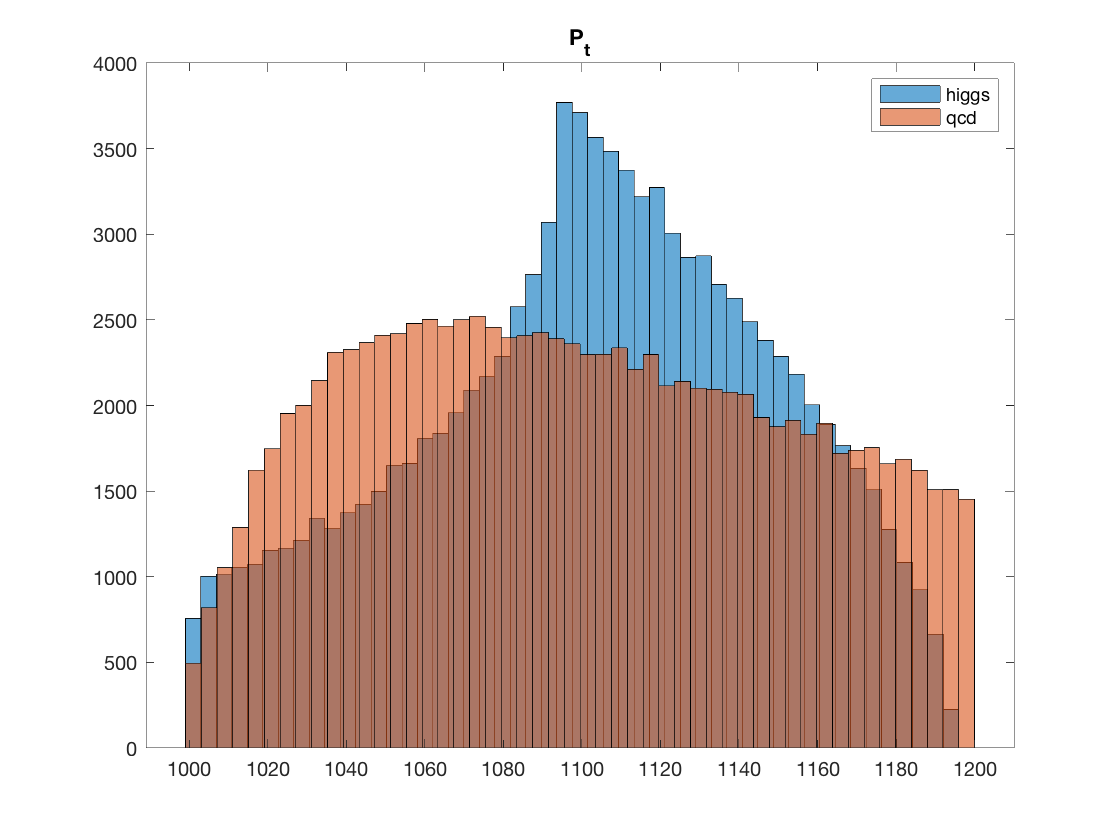


histogram(higgs(1,:),50)
hold on
histogram(qcd(1,:),50)
hold off
title('P_{t}')
legend('higgs','qcd')

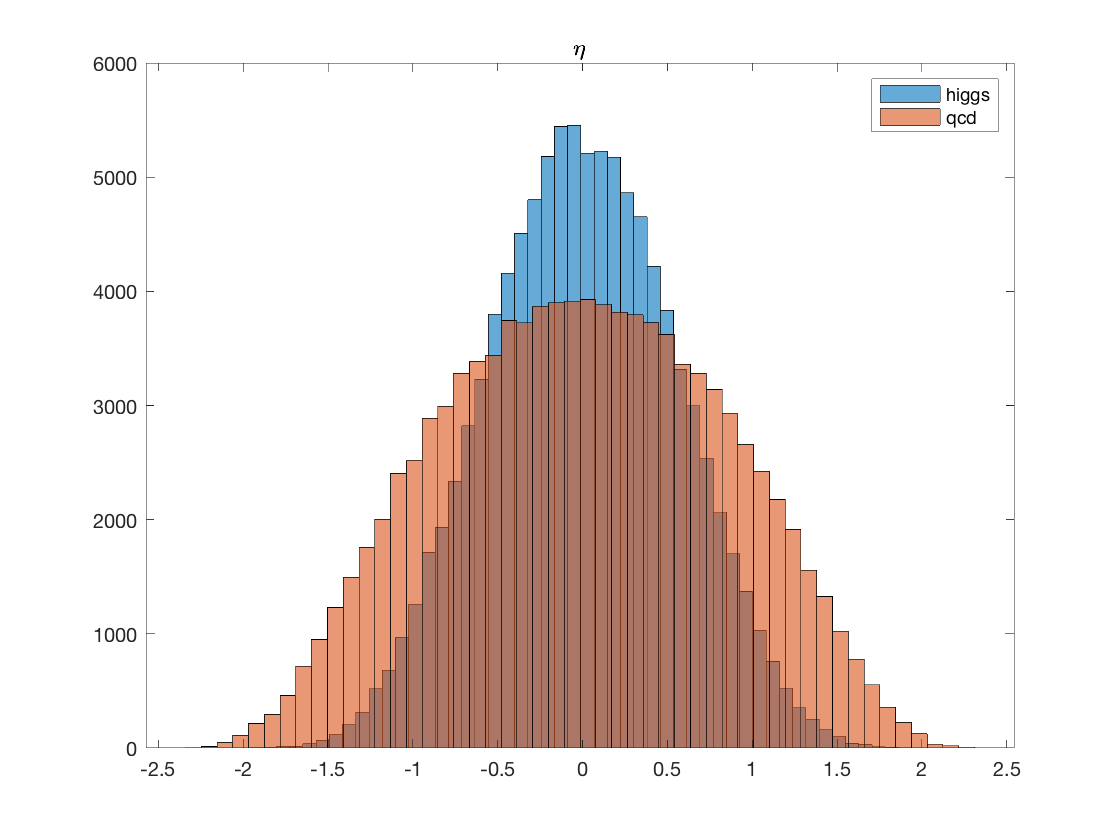

histogram(higgs(2,:),50)
hold on
histogram(qcd(2,:),50)
hold off
title('\eta')
legend('higgs','qcd')

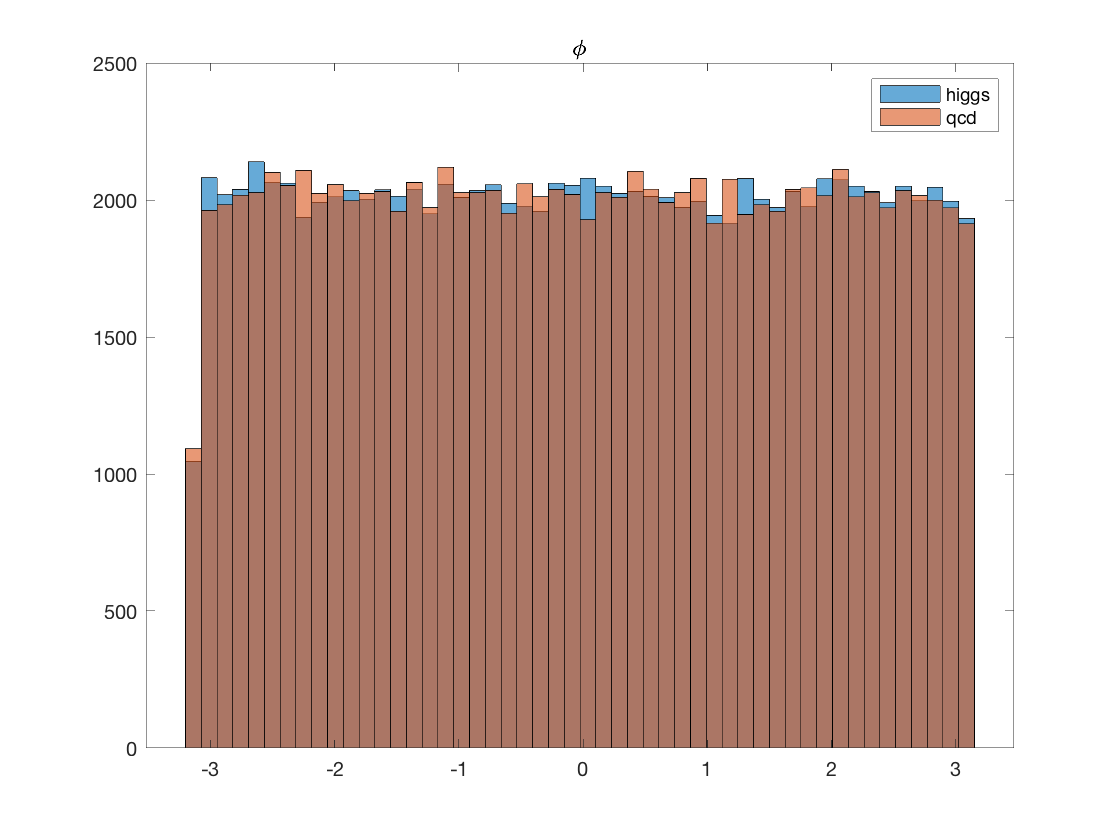

histogram(higgs(3,:),50)
hold on
histogram(qcd(3,:),50)
hold off
title('\phi')
legend('higgs','qcd')

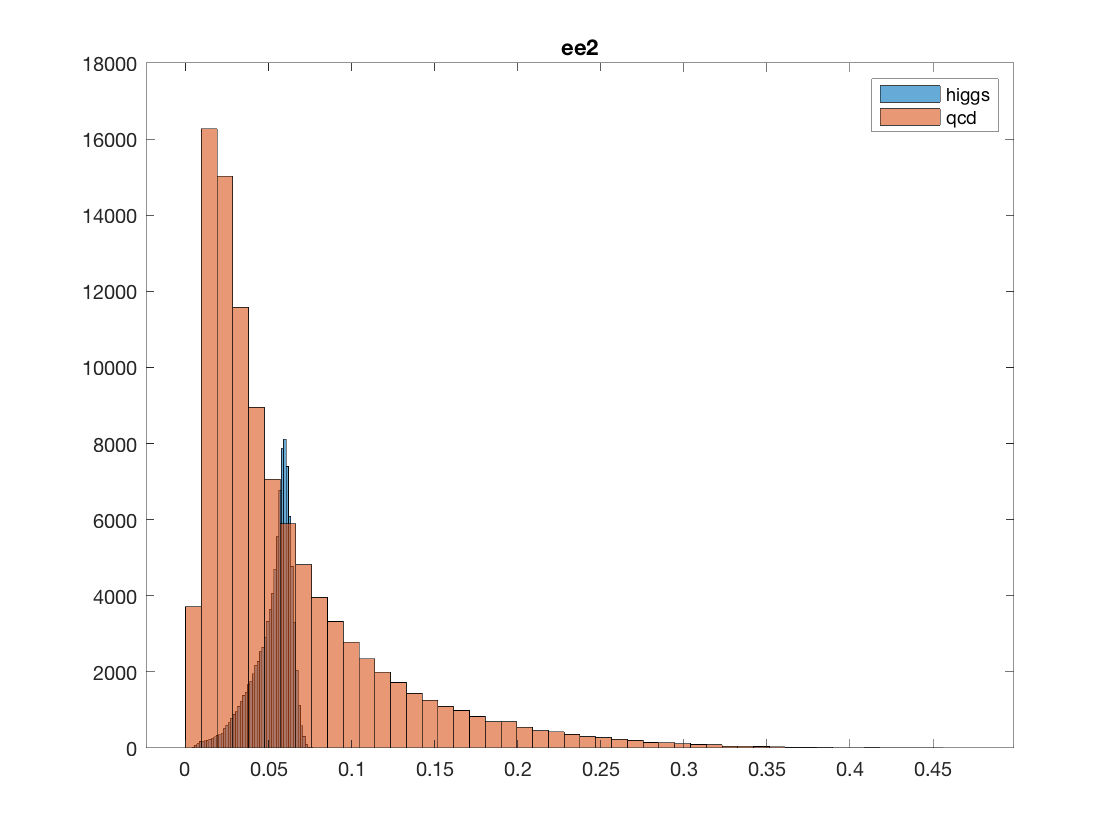

histogram(higgs(5,:),50)
hold on
histogram(qcd(5,:),50)
hold off
title('ee2')
legend('higgs','qcd')

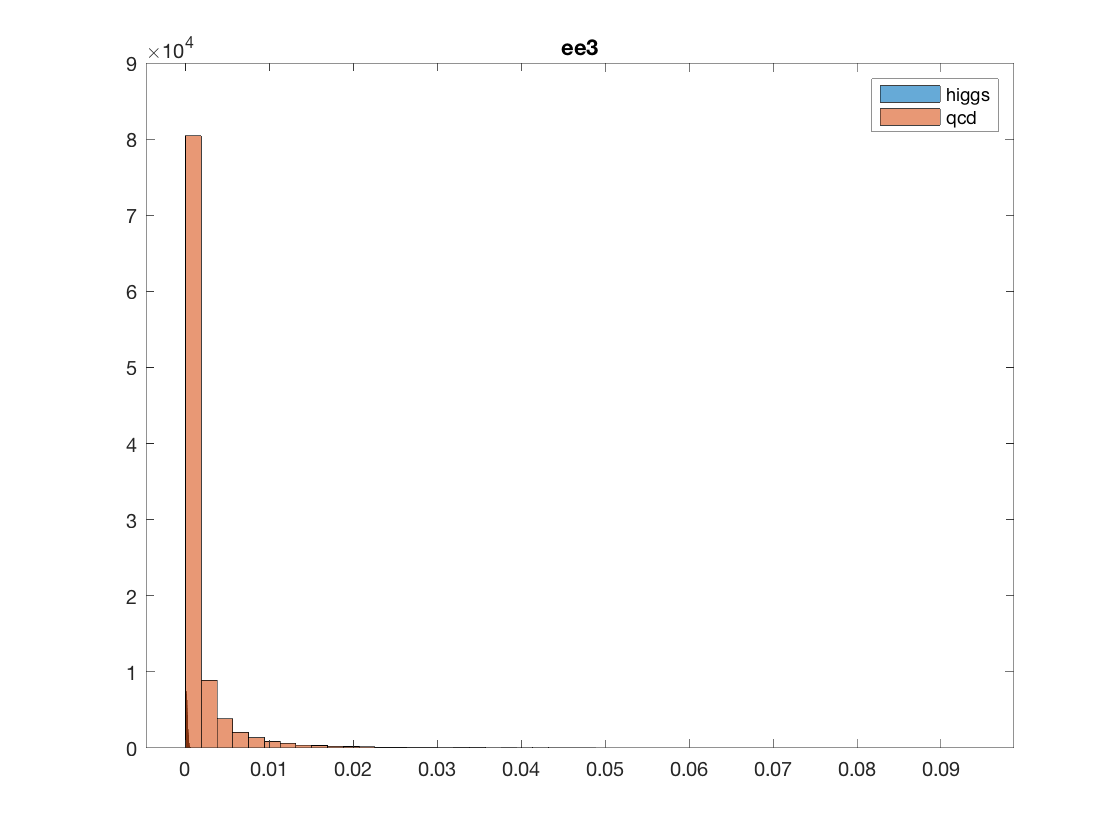

histogram(higgs(6,:),50)
hold on
histogram(qcd(6,:),50)
hold off
title('ee3')
legend('higgs','qcd')

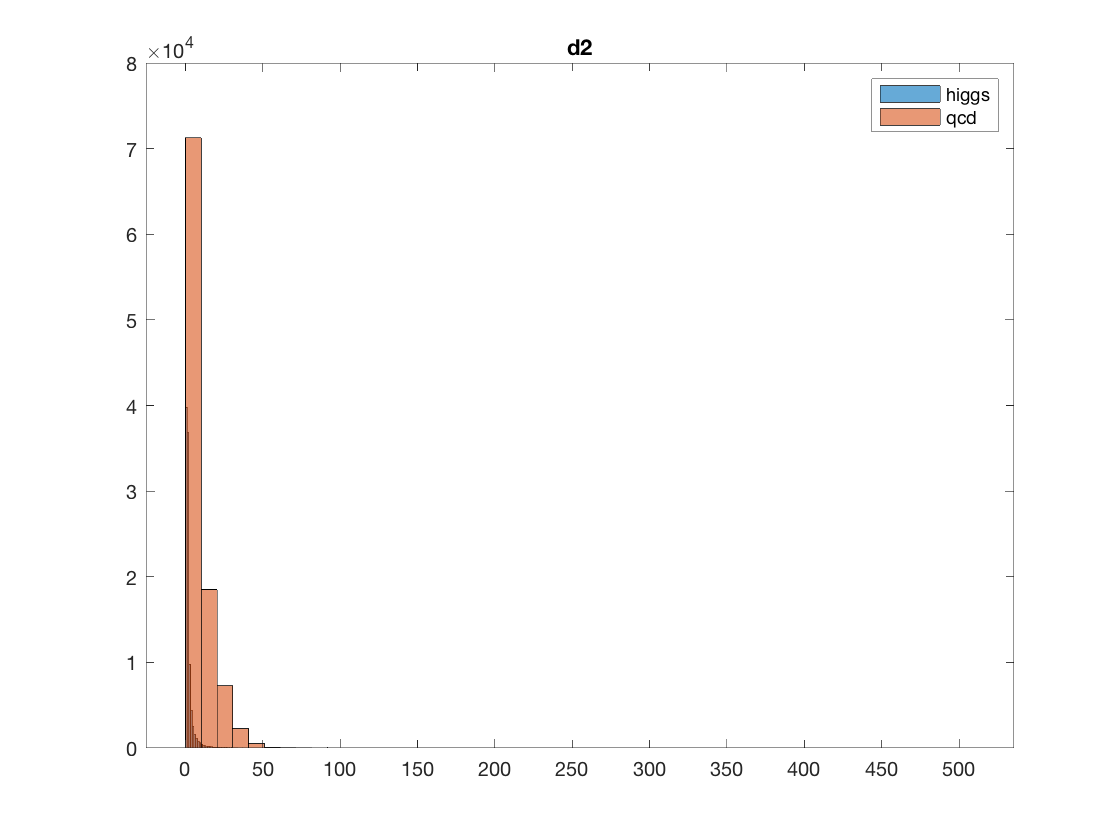

histogram(higgs(7,:),50)
hold on
histogram(qcd(7,:),50)
hold off
title('d2')
legend('higgs','qcd')

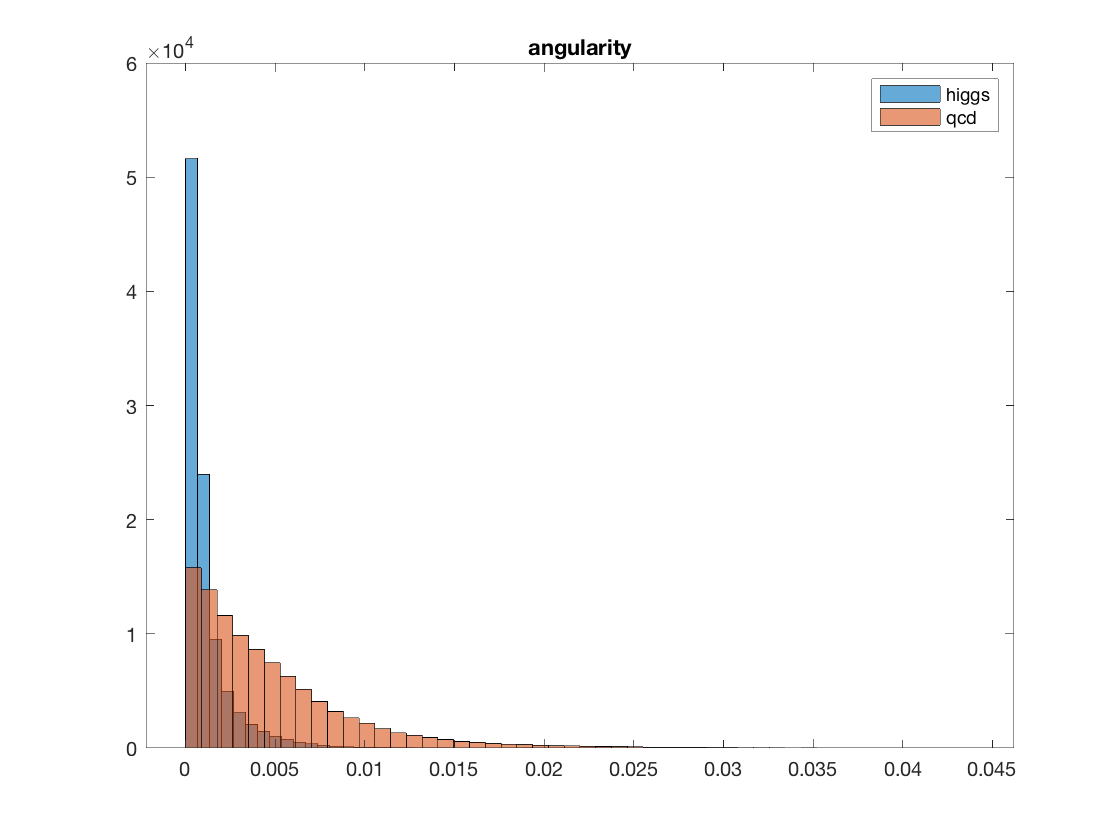

histogram(higgs(8,:),50)
hold on
histogram(qcd(8,:),50)
hold off
title('angularity')
legend('higgs','qcd')

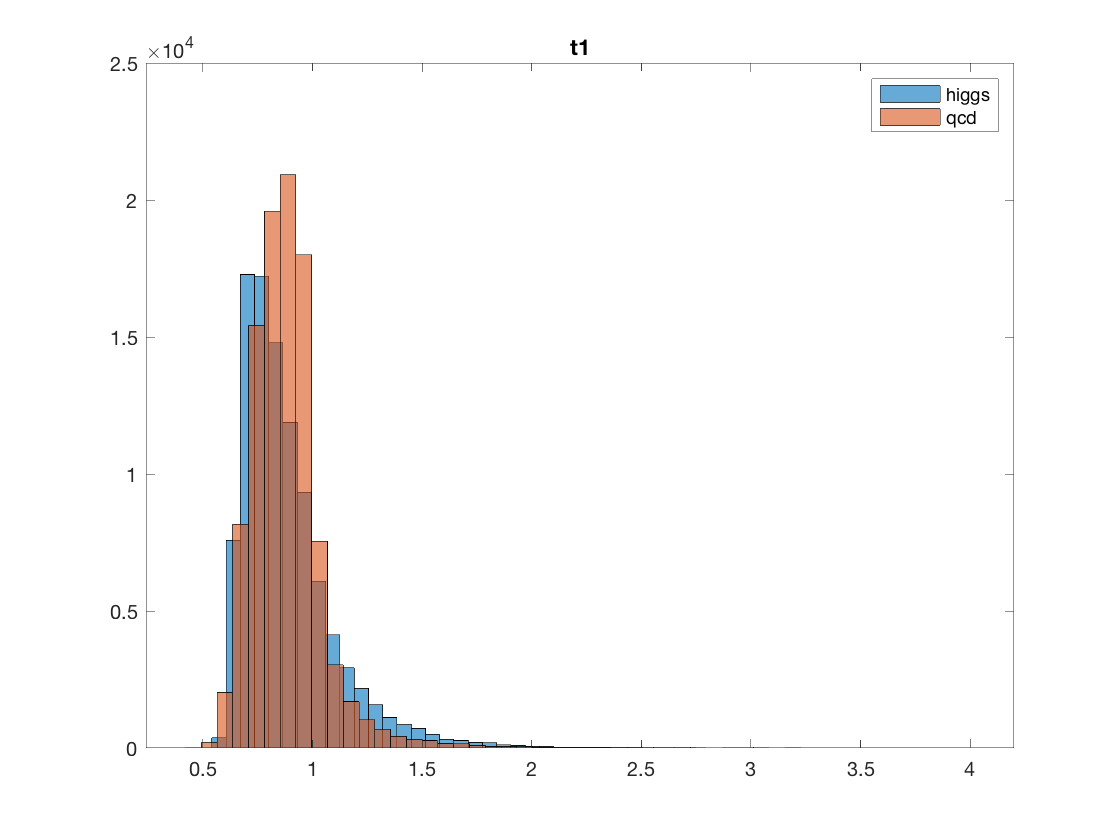

histogram(higgs(9,:),50)
hold on
histogram(qcd(9,:),50)
hold off
title('t1')
legend('higgs','qcd')

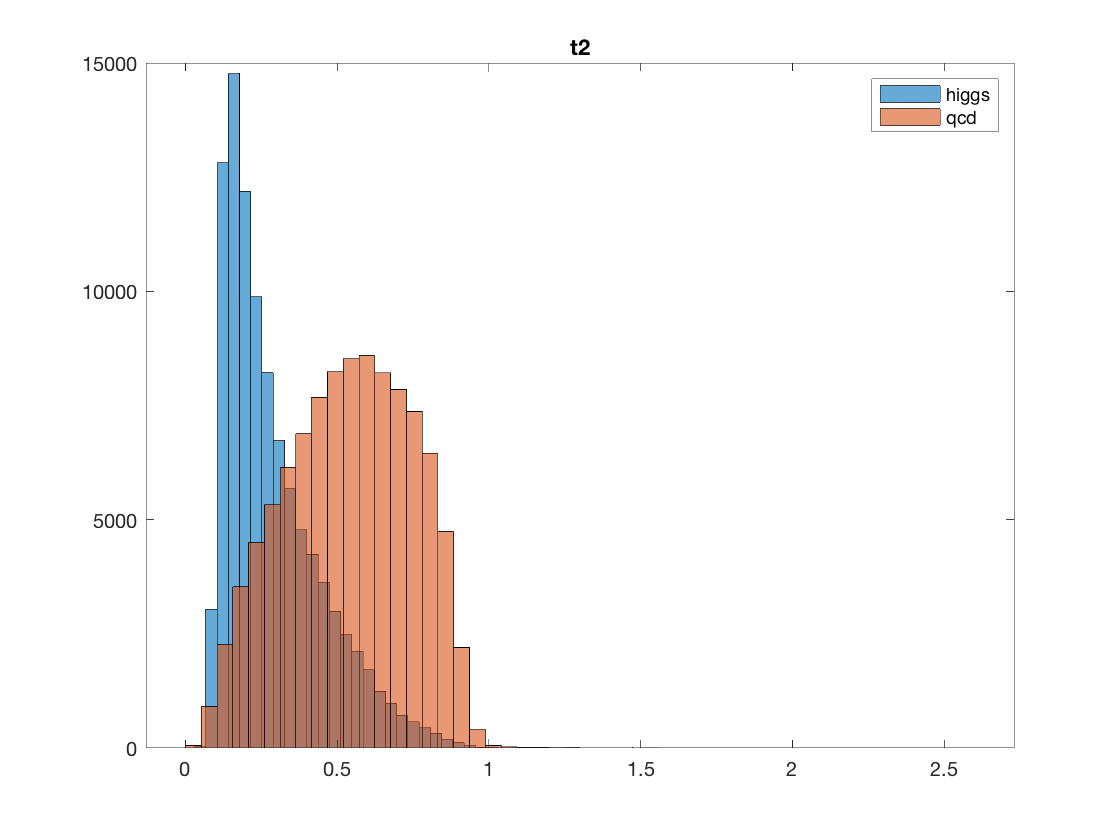

histogram(higgs(10,:),50)
hold on
histogram(qcd(10,:),50)
hold off
title('t2')
legend('higgs','qcd')

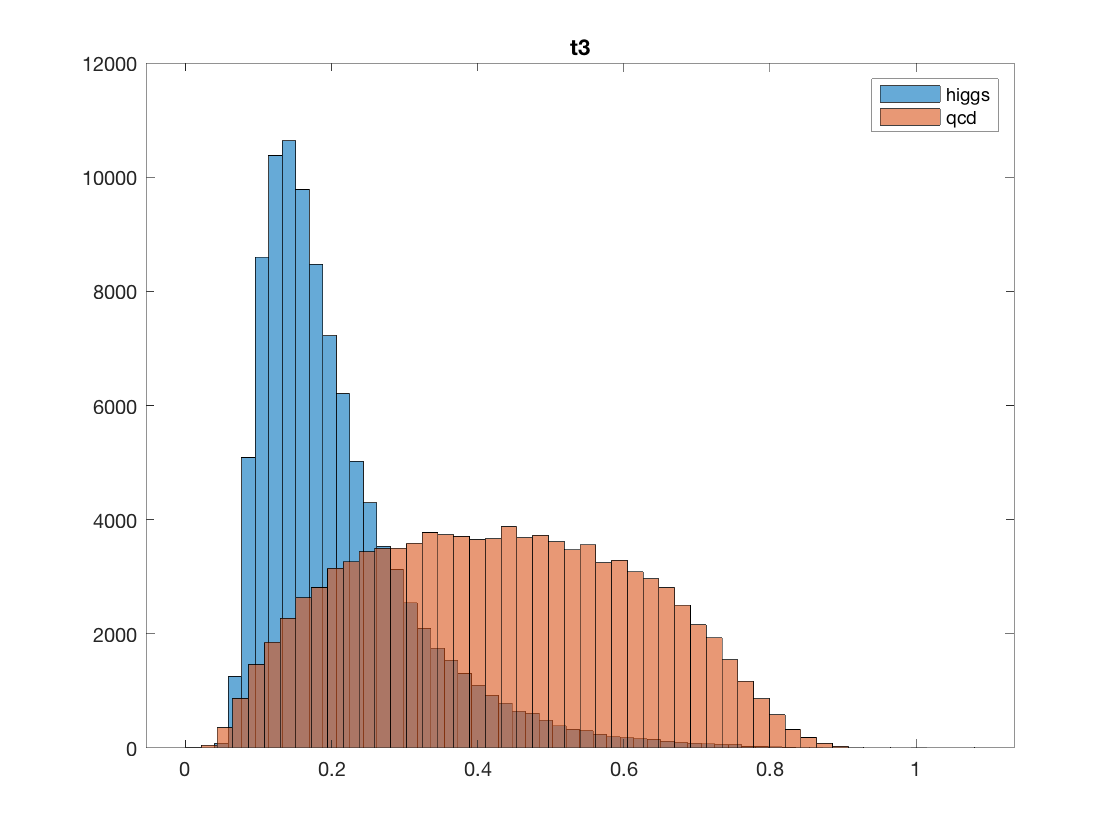

histogram(higgs(11,:),50)
hold on
histogram(qcd(11,:),50)
hold off
title('t3')
legend('higgs','qcd')

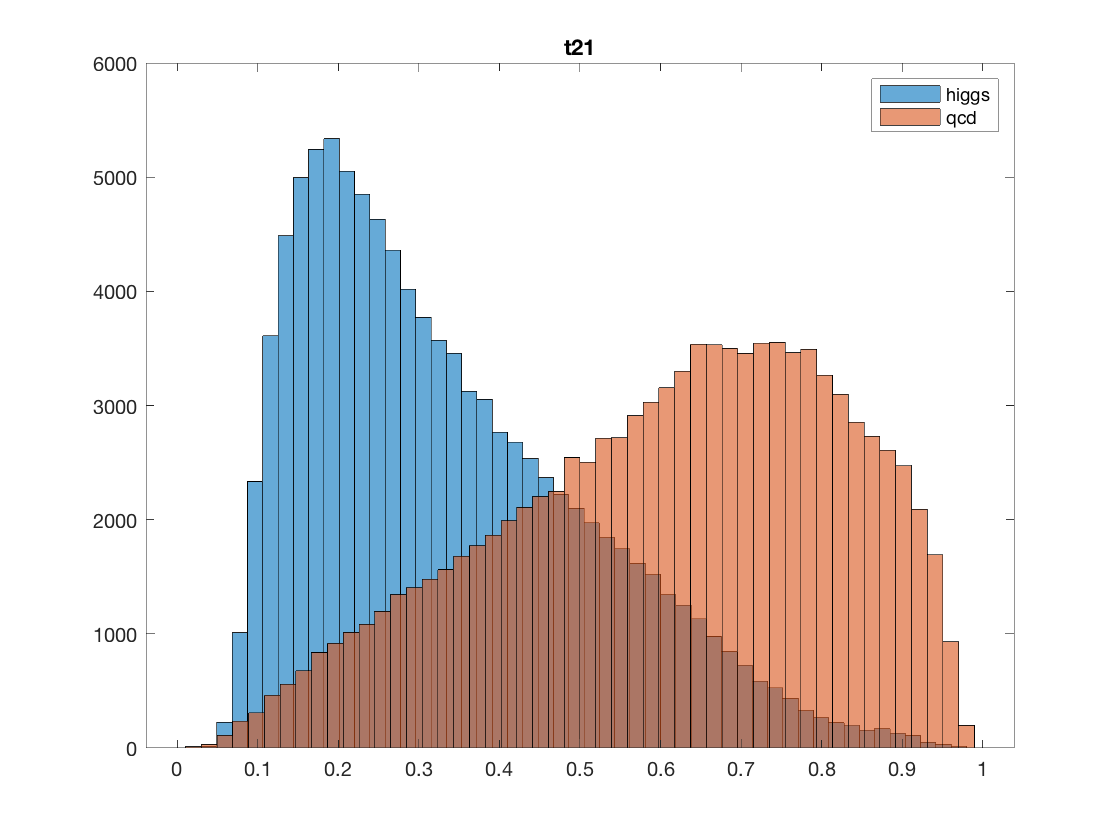

histogram(higgs(12,:),50)
hold on
histogram(qcd(12,:),50)
hold off
title('t21')
legend('higgs','qcd')

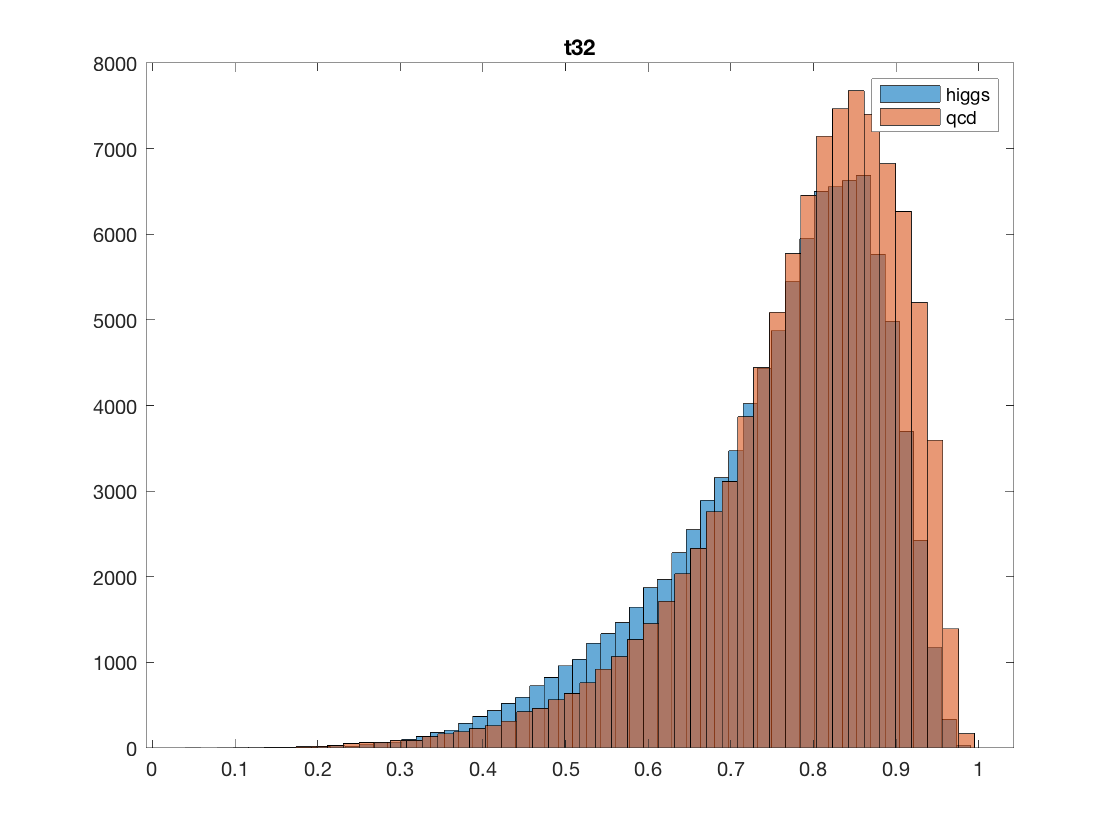

histogram(higgs(13,:),50)
hold on
histogram(qcd(13,:),50)
hold off
title('t32')
legend('higgs','qcd')

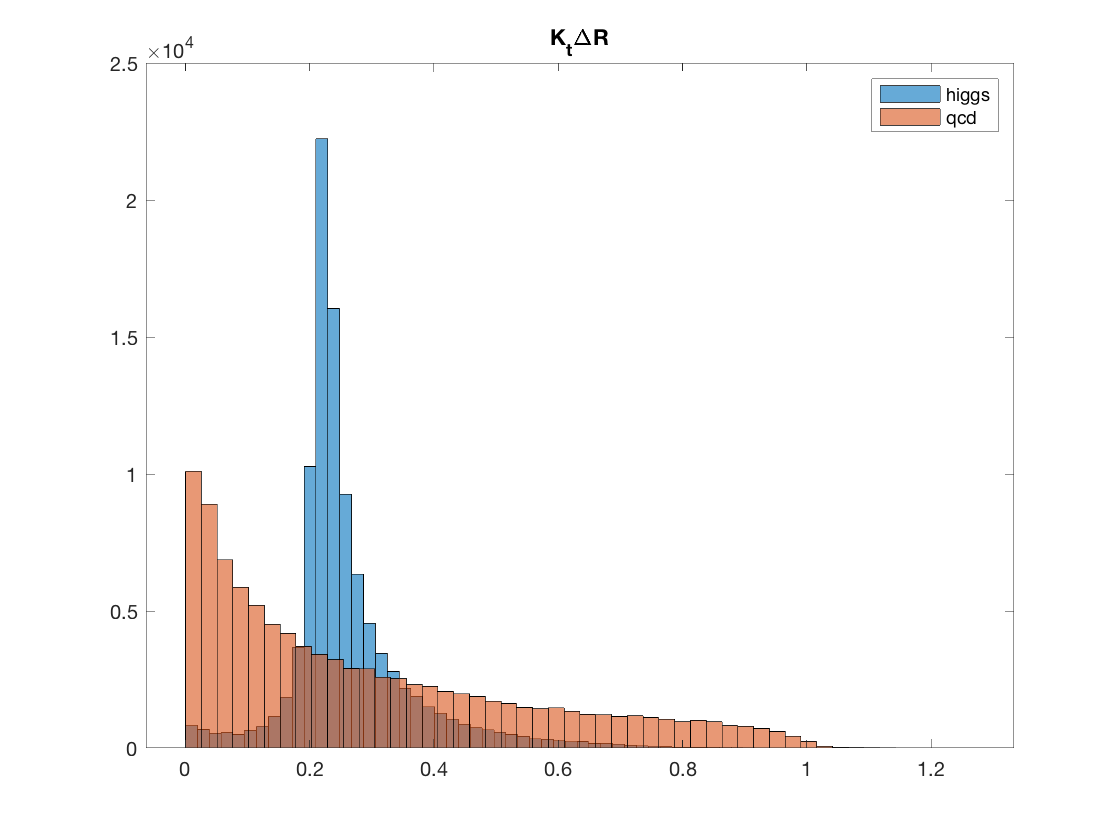

histogram(higgs(14,:),50)
hold on
histogram(qcd(14,:),50)
hold off
title('K_{t}\DeltaR')
legend('higgs','qcd')

According to the plots, ee2, t2,t3,t21, and KtDeltaR are the features that are discriminative. Among those features, KtDeltaR is about discriminative as the mass feature because the KtDeltaR distribution in Higgs data and QCD data has a very clear seperation. Therefore, the expected significance of KtDeltaR after the mass cut will be improved by a lot.

In this part, I am going to perform the mass cut on ktdeltaR feature. I will follow the exact same procedure I did when doing mass cut on the mass feature. I first fit the ktdeltaR feature in both QCD and Higgs data with a Poisson distribution. Then I find the cut that optimize $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$. 

The code below finds the cut that optimize the ratio.


ktdeltR_higgs = higgs(14,:);
ktdeltR_qcd = qcd(14,:);


binranges_qcd = linspace(0,max(ktdeltR_qcd),1000);
binranges_higgs = linspace(min(ktdeltR_higgs),max(ktdeltR_higgs),1000);
pd_qcd = histc(ktdeltR_qcd,binranges_qcd)/100000;
pd_higgs = histc(ktdeltR_higgs,binranges_higgs)/100000;
cent = binranges_higgs(pd_higgs==max(pd_higgs));

cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    

    
    i_higgs_r = binranges_higgs>=mean(ktdeltR_higgs)+cut(i)/100;
    i_higgs_l = binranges_higgs<=mean(ktdeltR_higgs)-cut(i)/100;
    i_qcd_r = binranges_qcd>=mean(ktdeltR_higgs)+cut(i)/100;
    i_qcd_l = binranges_qcd<=mean(ktdeltR_higgs)-cut(i)/100;
    
    P_higgs = 1-sum(pd_higgs(i_higgs_l))-sum(pd_higgs(i_higgs_r));
    P_qcd = 1-sum(pd_qcd(i_qcd_l))-sum(pd_qcd(i_qcd_r));
    

   
    ratio(i) = 50*P_higgs/sqrt(2000*P_qcd);
end
cut_opti = cut(ratio==max(ratio))/100;

After I run the code, it is found that when throwing away the data that is smaller than 0.26-0.06 and the data that is greater than 0.26+0.06. The ratio $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$ is optimized. (0.26 is the mean of the ktdeltaR in Higgs data)

Since we have found the optimal cut of the data, we should plot Higgs and QCD data after the cuts. To cut the data, I will throw away any KtdeltaR data that is beyond the range [0.26-0.06,0.26+0.06] from the Higgs and QCD data.

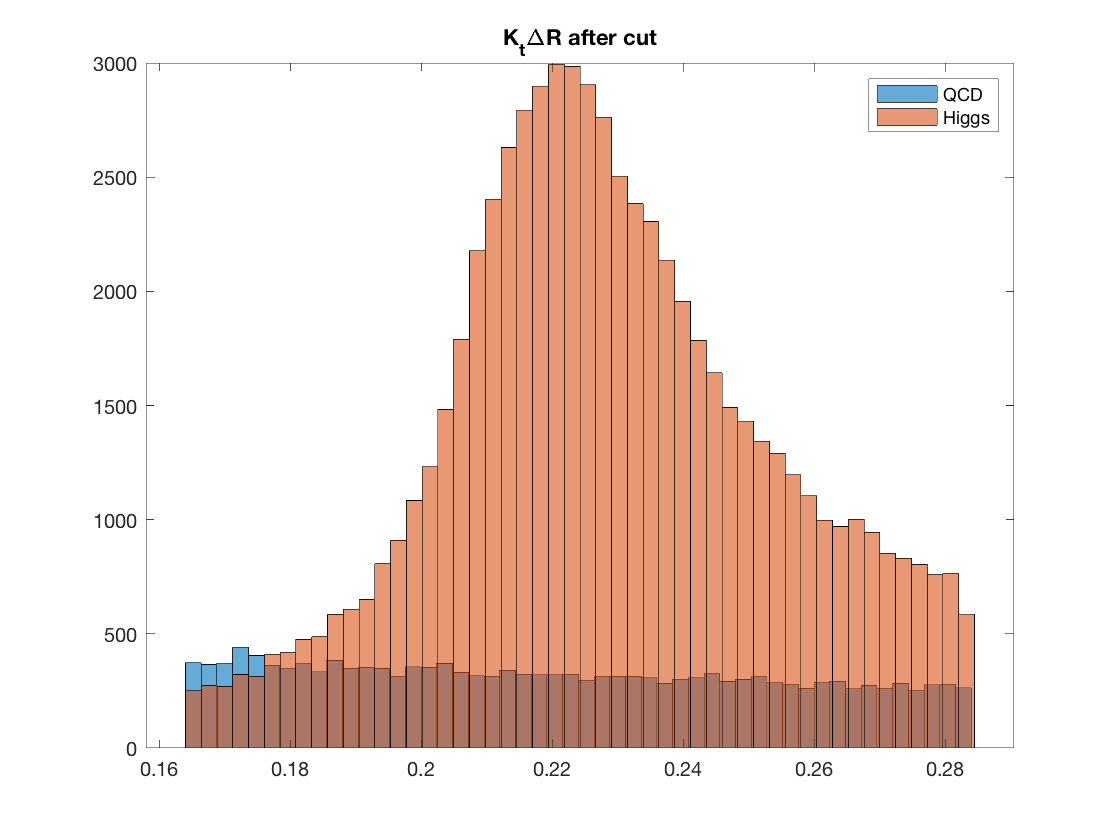


ktdeltR_higgs(ktdeltR_higgs<cent-cut_opti) = [];
ktdeltR_higgs(ktdeltR_higgs>cent+cut_opti) = [];
ktdeltR_qcd(ktdeltR_qcd<cent-cut_opti) = [];
ktdeltR_qcd(ktdeltR_qcd>cent+cut_opti) = [];

histogram(ktdeltR_qcd,50);
hold on
histogram(ktdeltR_higgs,50);
title('K_{t}\DeltaR after cut')
legend('QCD','Higgs')
hold off

The optimized ratio after cuts for the ktdeltR feature is 1.9987. It has some improvement but not as great as the improvement on mass feature after cut.

## Problem 4

By looking at the histograms of every feature, the seperation of Higgs and QCD data in the t21 feature is the furthest among all 14 features. Therefore, it will be interesting to do the cut on t21 feature and calculate the significance after cut. Same as what we did in the previous sections, we start with fitting the data with Poisson distribution. A formal way to fit the data is using the function in matlab named "fitdist". However, this function does not work very well in this context because what it does is finding the parameter of Poisson distribution "lambda" by finding the mean of the data. Based on the shape of the data, Poisson is a very "crude" fitting and choosing the mean of the data to be lambda will not give us a distribution that captures the shape of the original data. Therefore, I am going to convert the data distribution to probability distribution directly.

The code below will do the cut by following the procedures of the previous sections.

clear t

t21_higgs = higgs(12,:);
t21_qcd = qcd(12,:);


binranges_qcd = linspace(0,max(t21_qcd),1000);
binranges_higgs = linspace(min(t21_higgs),max(t21_higgs),1000);
pd_qcd = histc(t21_qcd,binranges_qcd)/100000;
pd_higgs = histc(t21_higgs,binranges_higgs)/100000;
cent = binranges_higgs(pd_higgs==max(pd_higgs));

cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    

    
    i_higgs_r = binranges_higgs>=mean(t21_higgs)+cut(i)/100;
    i_higgs_l = binranges_higgs<=mean(t21_higgs)-cut(i)/100;
    i_qcd_r = binranges_qcd>=mean(t21_higgs)+cut(i)/100;
    i_qcd_l = binranges_qcd<=mean(t21_higgs)-cut(i)/100;
    
    P_higgs = 1-sum(pd_higgs(i_higgs_l))-sum(pd_higgs(i_higgs_r));
    P_qcd = 1-sum(pd_qcd(i_qcd_l))-sum(pd_qcd(i_qcd_r));
    

   
    ratio(i) = 50*P_higgs/sqrt(2000*P_qcd);
end
cut_opti = cut(ratio==max(ratio))/100;

In the end, I found that throwing away t21 data that is beyond [0.2-0.24,0.2+0.24] rang in both Higgs and QCD data will give us the optimal $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{qcd}} }}$ ratio. 

The optimized ratio is 1.5385. It has some improvements but not as much as the improvement on the mass feature after cuts.

Let's plot the data after cut and calculate the significance below.

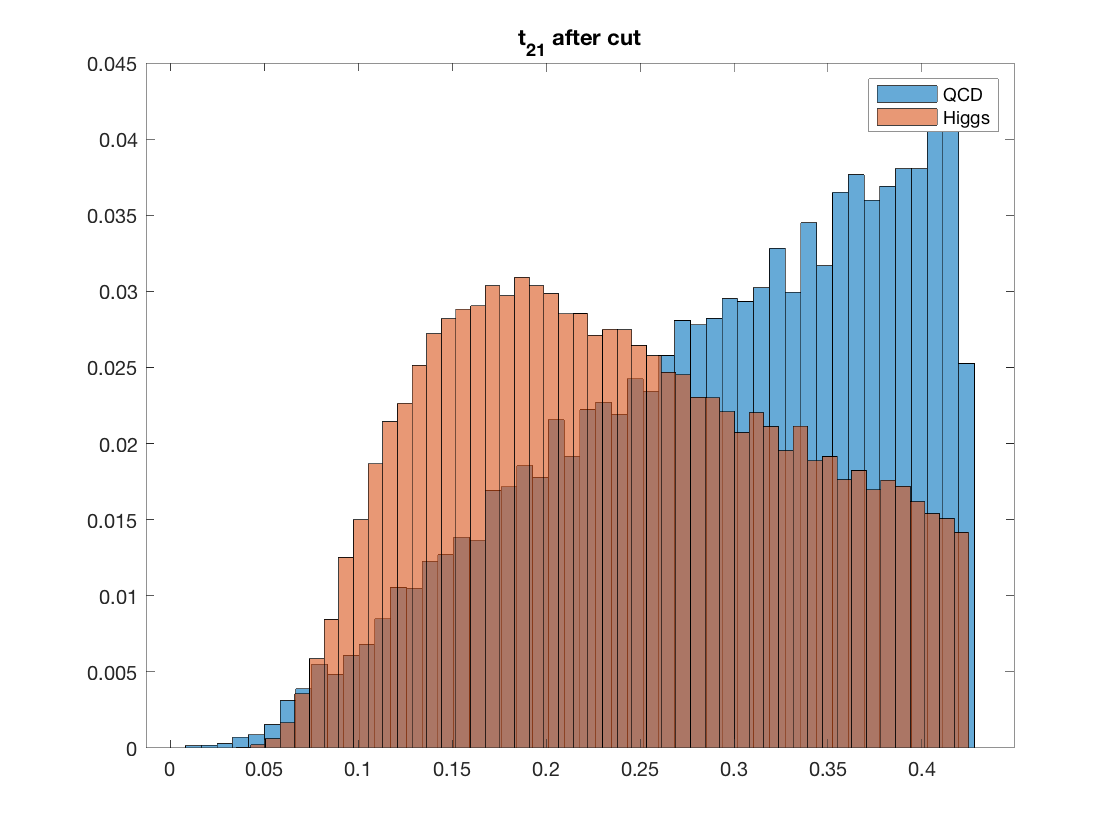

t21_higgs(t21_higgs<cent-cut_opti) = [];
t21_higgs(t21_higgs>cent+cut_opti) = [];
t21_qcd(t21_qcd<cent-cut_opti) = [];
t21_qcd(t21_qcd>cent+cut_opti) = [];

histogram(t21_qcd,50,'Normalization','probability');
hold on
histogram(t21_higgs,50,'Normalization','probability');
title('t_{21} after cut')
legend('QCD','Higgs')
hold off

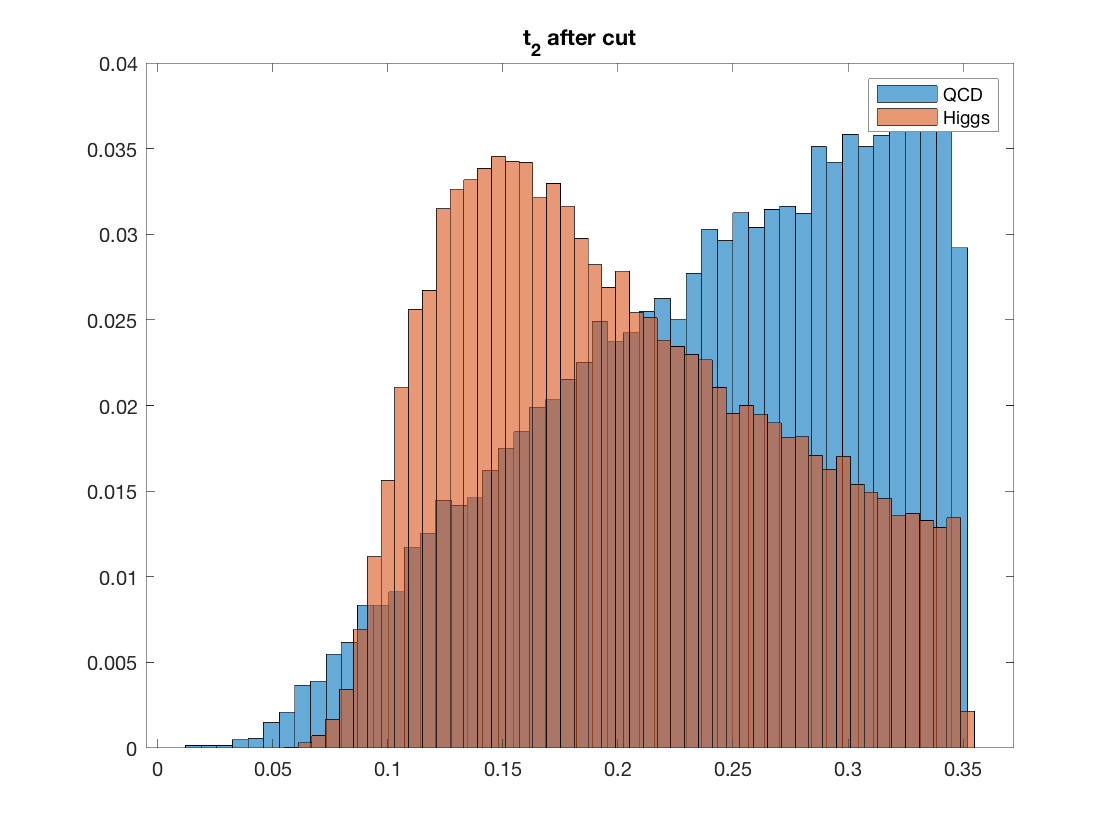


clear t

t2_higgs = higgs(10,:);
t2_qcd = qcd(10,:);



binranges_qcd = linspace(0,max(t2_qcd),1000);
binranges_higgs = linspace(min(t2_higgs),max(t2_higgs),1000);
pd_qcd = histc(t2_qcd,binranges_qcd)/100000;
pd_higgs = histc(t2_higgs,binranges_higgs)/100000;
cent = binranges_higgs(pd_higgs==max(pd_higgs));

cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    

    
    i_higgs_r = binranges_higgs>=mean(t2_higgs)+cut(i)/100;
    i_higgs_l = binranges_higgs<=mean(t2_higgs)-cut(i)/100;
    i_qcd_r = binranges_qcd>=mean(t2_higgs)+cut(i)/100;
    i_qcd_l = binranges_qcd<=mean(t2_higgs)-cut(i)/100;
    
    P_higgs = 1-sum(pd_higgs(i_higgs_l))-sum(pd_higgs(i_higgs_r));
    P_qcd = 1-sum(pd_qcd(i_qcd_l))-sum(pd_qcd(i_qcd_r));
    

   
    ratio(i) = 50*P_higgs/sqrt(2000*P_qcd);
end
cut_opti = cut(ratio==max(ratio))/100;

t2_higgs(t2_higgs<cent-cut_opti) = [];
t2_higgs(t2_higgs>cent+cut_opti) = [];
t2_qcd(t2_qcd<cent-cut_opti) = [];
t2_qcd(t2_qcd>cent+cut_opti) = [];

histogram(t2_qcd,50,'Normalization','probability');
hold on
histogram(t2_higgs,50,'Normalization','probability');
title('t_{2} after cut')
legend('QCD','Higgs')
hold off

The ratio of t2 after cut is 1.5305. The improvement is not as much as the improvement of mass feature after cuts.

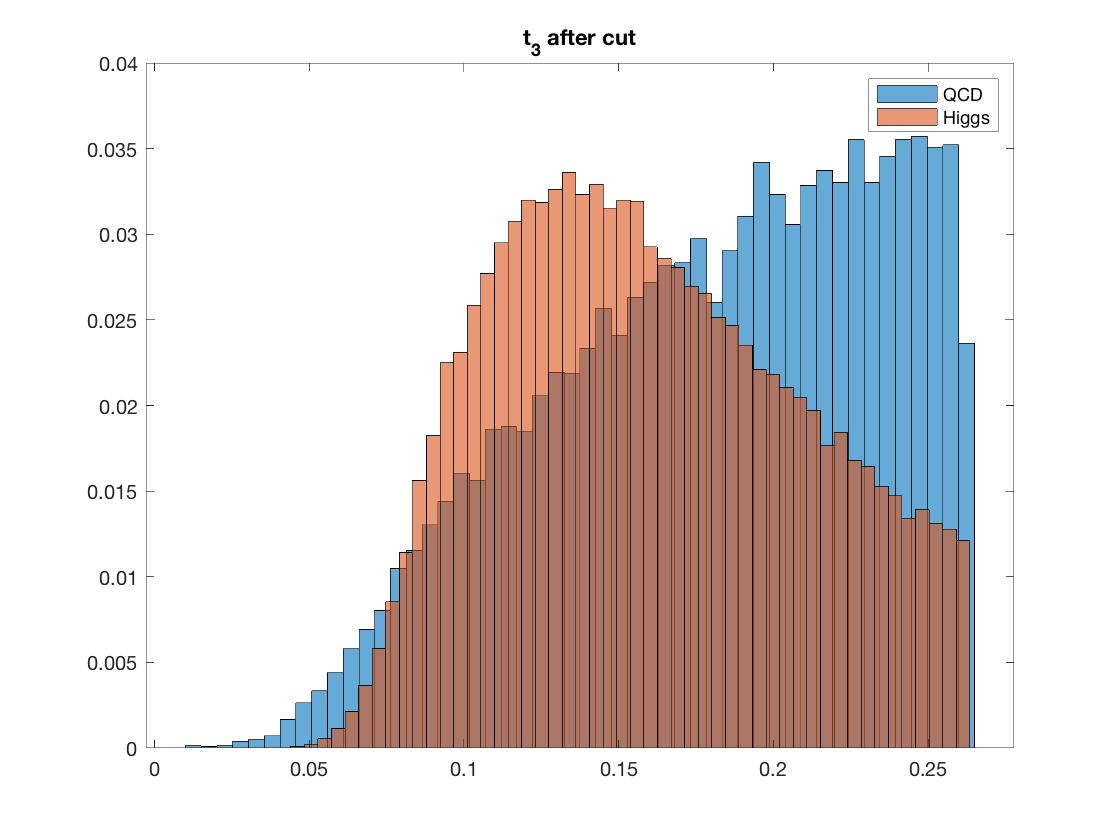


clear t

t3_higgs = higgs(11,:);
t3_qcd = qcd(11,:);


binranges_qcd = linspace(0,max(t3_qcd),1000);
binranges_higgs = linspace(min(t3_higgs),max(t3_higgs),1000);
pd_qcd = histc(t3_qcd,binranges_qcd)/100000;
pd_higgs = histc(t3_higgs,binranges_higgs)/100000;
cent = binranges_higgs(pd_higgs==max(pd_higgs));

cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    

    
    i_higgs_r = binranges_higgs>=mean(t3_higgs)+cut(i)/100;
    i_higgs_l = binranges_higgs<=mean(t3_higgs)-cut(i)/100;
    i_qcd_r = binranges_qcd>=mean(t3_higgs)+cut(i)/100;
    i_qcd_l = binranges_qcd<=mean(t3_higgs)-cut(i)/100;
    
    P_higgs = 1-sum(pd_higgs(i_higgs_l))-sum(pd_higgs(i_higgs_r));
    P_qcd = 1-sum(pd_qcd(i_qcd_l))-sum(pd_qcd(i_qcd_r));
    

   
    ratio(i) = 50*P_higgs/sqrt(2000*P_qcd);
end
cut_opti = cut(ratio==max(ratio))/100;

t3_higgs(t3_higgs<cent-cut_opti) = [];
t3_higgs(t3_higgs>cent+cut_opti) = [];
t3_qcd(t3_qcd<cent-cut_opti) = [];
t3_qcd(t3_qcd>cent+cut_opti) = [];

histogram(t3_qcd,50,'Normalization','probability');
hold on
histogram(t3_higgs,50,'Normalization','probability');
title('t_{3} after cut')
legend('QCD','Higgs')
hold off

The optimized ratio for the t3 feature is 1.6620. The improvement is not as much as the mass feature.

Based on the results from the previous sections, KtdeltaR, t21, t2, and t3 have some improvement in significance after cut. Among those feautre the improvement on the mass feature was the greates. The ratio went from 1.18 to about 4.5.

## Lab8

In lab 8, I am going to perform data analysis on a pseudo-experiment data with the optimal event selection developed in lab 7. 

First of all, I loaded both the high luminosity and low luminosity data.


clear all
close all
clc

h5disp('data_highLumi_pt_1000_1200.h5')

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

highlumi = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
h5disp('data_lowLumi_pt_1000_1200.h5')

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute

lowlumi = h5read('data_lowLumi_pt_1000_1200.h5','/data/block0_values');
variables = h5read('data_lowLumi_pt_1000_1200.h5','/data/block0_items');

h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');


After loading the data, I am going to plot the mass feature of the low luminosity data and overlap the graph with the expected signal and background. The expected signal and background is basically the data we get from the simulation. Since the simulated data has 10000 points for Higgs and QCD, I am going to normalize the simulated data to the expected yields.

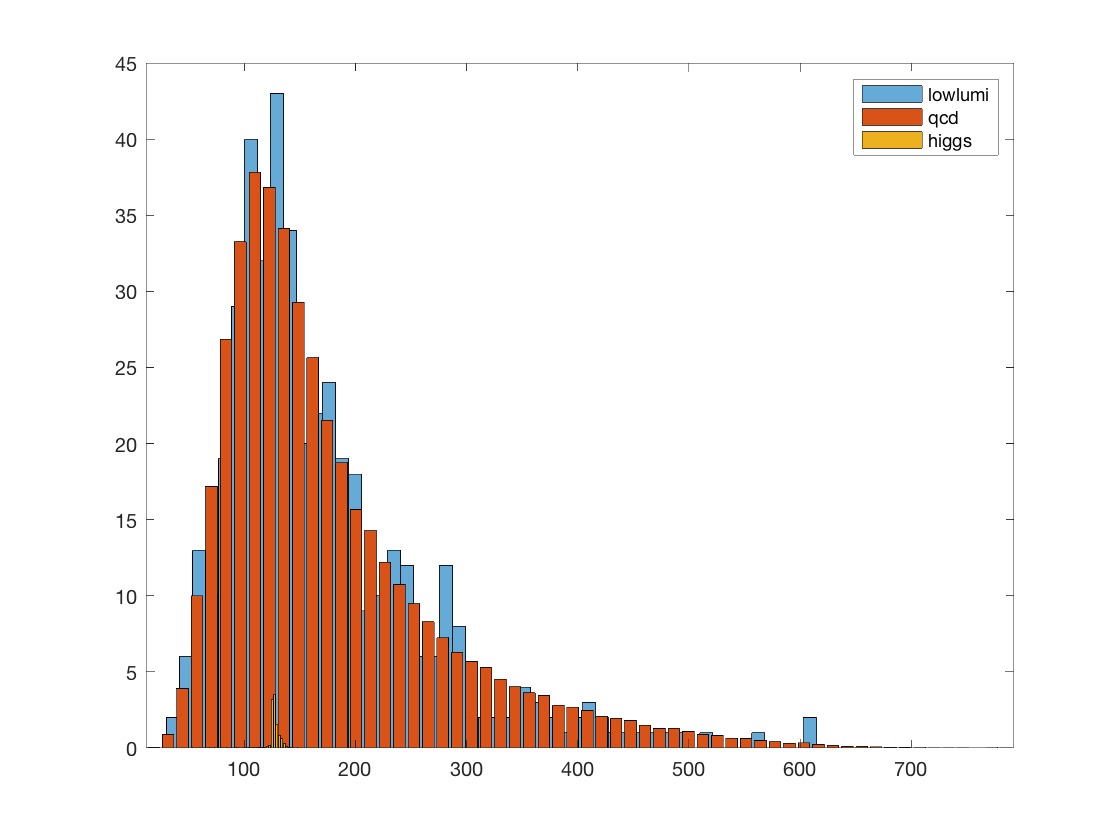

mass_qcd = qcd(4,:);
mass_higgs = higgs(4,:);
mass_lowlumi = lowlumi(4,:);
l = length(lowlumi(1,:));
[C_higgs, Cen_higgs] = hist(mass_higgs,60);
[C_qcd, Cen_qcd] = hist(mass_qcd,60);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;

histogram(lowlumi(4,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('lowlumi','qcd','higgs')
hold off

I normalized the simulated data by finding the probability distribution of the data. Then I multiply the probability distribution with the total numbers of low luminosity data. It is based on the math:


$$\begin{array}{l}
N_{\mathrm{mass}} =P_{\mathrm{mass}} *N_{\mathrm{tot}} \;\;,\mathrm{Where}\;P_{\mathrm{mass}\;} \mathrm{is}\;\mathrm{the}\;\mathrm{probability}\;\mathrm{of}\;\mathrm{measuring}\;a\;\mathrm{particular}\;\mathrm{mass}\\
N_{\mathrm{total}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{total}\;\mathrm{number}\;\mathrm{of}\;\mathrm{the}\;\mathrm{data}\;\mathrm{point}\ldotp N_{\mathrm{mass}} \;\mathrm{is}\;\mathrm{the}\;\mathrm{number}\;\mathrm{of}\;\mathrm{particles}\\
\mathrm{with}\;\mathrm{that}\;\mathrm{particluar}\;\mathrm{mass}\ldotp 
\end{array}$$


Since the number of QCD and Higgs data should add up to be the totoal number of low luminosity data. ($N_{\mathrm{qcd}} +N_{\mathrm{higgs}} =N_{\mathrm{lowlumi}}$) I also multiply the ratio 50/2050 to $N_{\mathrm{higgs}}$ and multiply 2000/2050 to $N_{\mathrm{qcd}}$ becuase the ratio of $\frac{N_{\mathrm{higgs}} }{N_{\mathrm{qcd}} }$ is 50/2000.

As the graph shows, the expected counts of QCD overlap the low luminosity data very well and the counts of Higgs data is very small compared to the counts of QCD and low luminosity data as expected. 

Now let's make plots after the cuts.


cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(mass_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(mass_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(mass_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(mass_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(mass_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end

Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

mass_lowlumi(mass_lowlumi<cent-cut_opti(1)) = [];
mass_lowlumi(mass_lowlumi>cent+cut_opti(1)) = [];

histogram(mass_lowlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('lowlumi','qcd','higgs')
hold off

After the cut, there were a few low luminosity data left. When I plot the low luminosity data and overlap with the expected Higgs and QCD data after cut. We can only see the Higgs data and the low luminosity data.

It seems that only the Higgs data were left after the cut. The significance has been grately improved because all the QCD data were thrown away and only Higgs data were kept.

In the following sections, I will performe the same procedures for features: t3 and KtdeltaR.

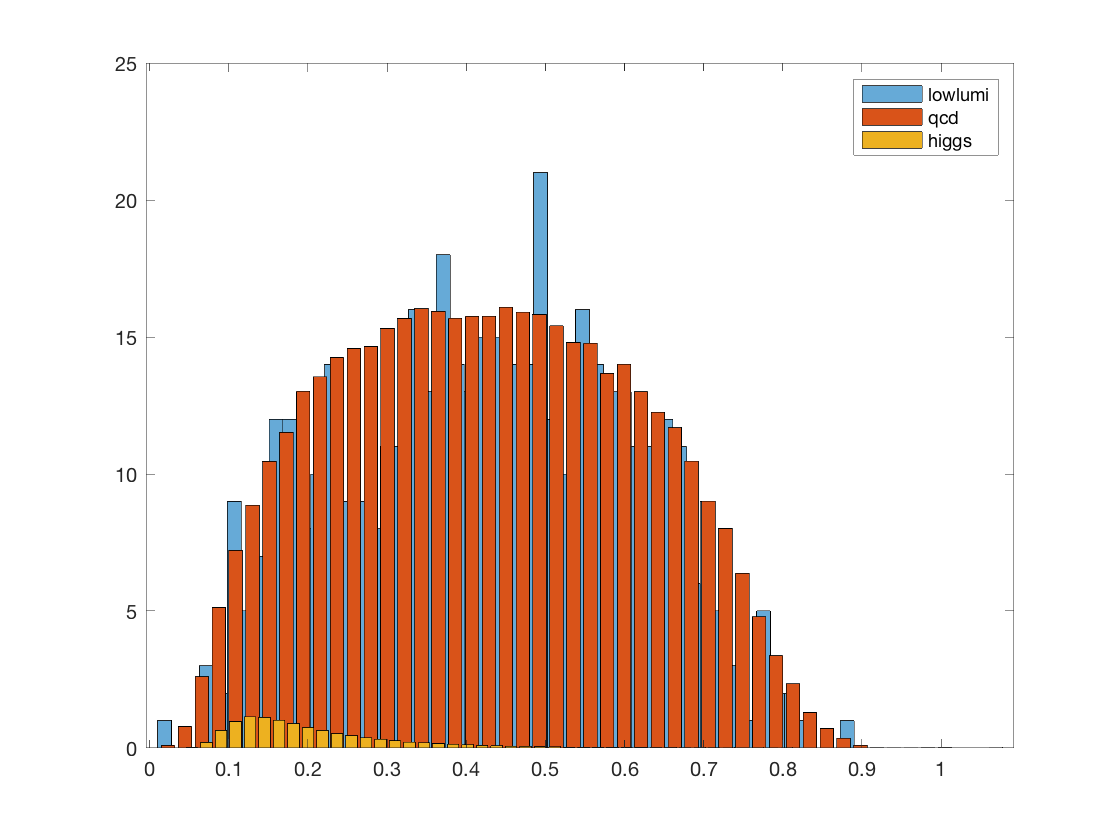


t3_qcd = qcd(11,:);
t3_higgs = higgs(11,:);
t3_lowlumi = lowlumi(11,:);
l = length(lowlumi(1,:));
[C_higgs, Cen_higgs] = hist(t3_higgs,50);
[C_qcd, Cen_qcd] = hist(t3_qcd,50);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;
r_original = sum(C_higgs)/sqrt(sum(C_qcd));
histogram(lowlumi(11,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('lowlumi','qcd','higgs')
hold off

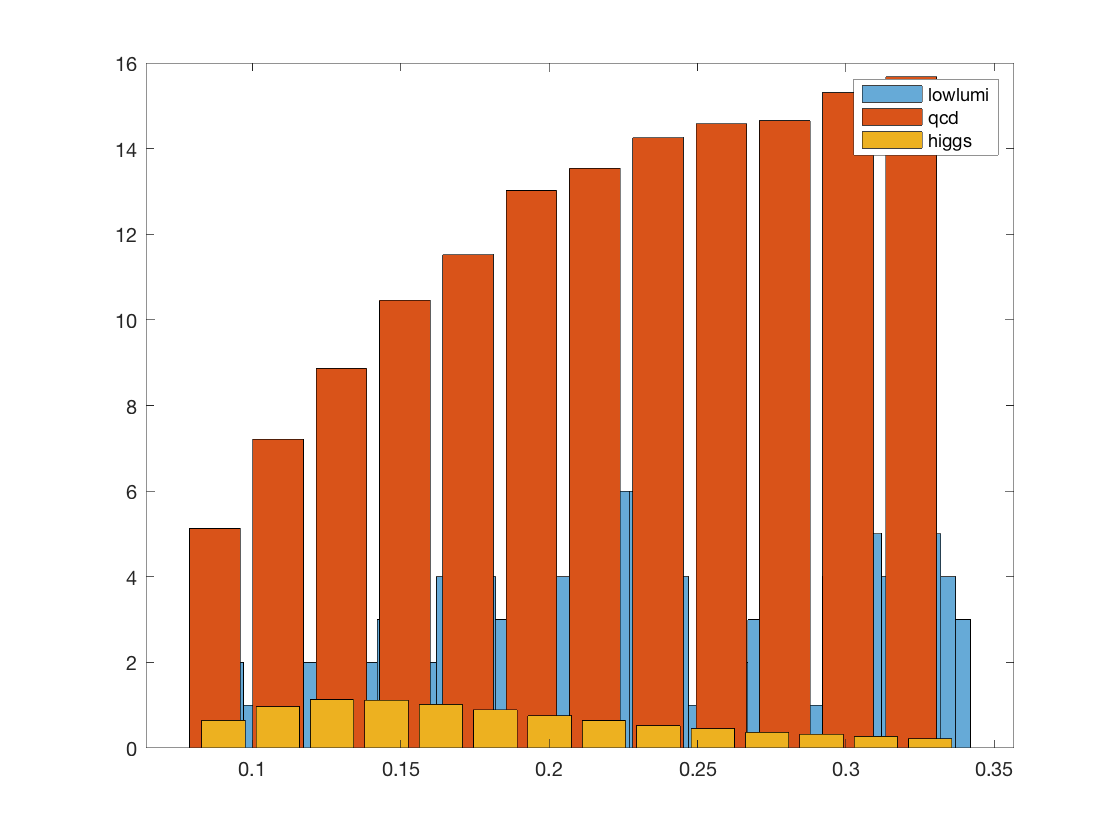


cut = 1:1:100;
cut = flip(cut);
cut = cut./100;
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(t3_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(t3_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(t3_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(t3_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(t3_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end
r_opti = sum(C_higgs)/sqrt(sum(C_qcd));
Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

t3_lowlumi(t3_lowlumi<cent-cut_opti(1)) = [];
t3_lowlumi(t3_lowlumi>cent+cut_opti(1)) = [];

histogram(t3_lowlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('lowlumi','qcd','higgs')
hold off

The ratio  $\frac{N_{\mathrm{higgs}} }{N_{\mathrm{qcd}} }$ (significance) before the event selection was 0.5191.

The significance after event selection was 0.7525.

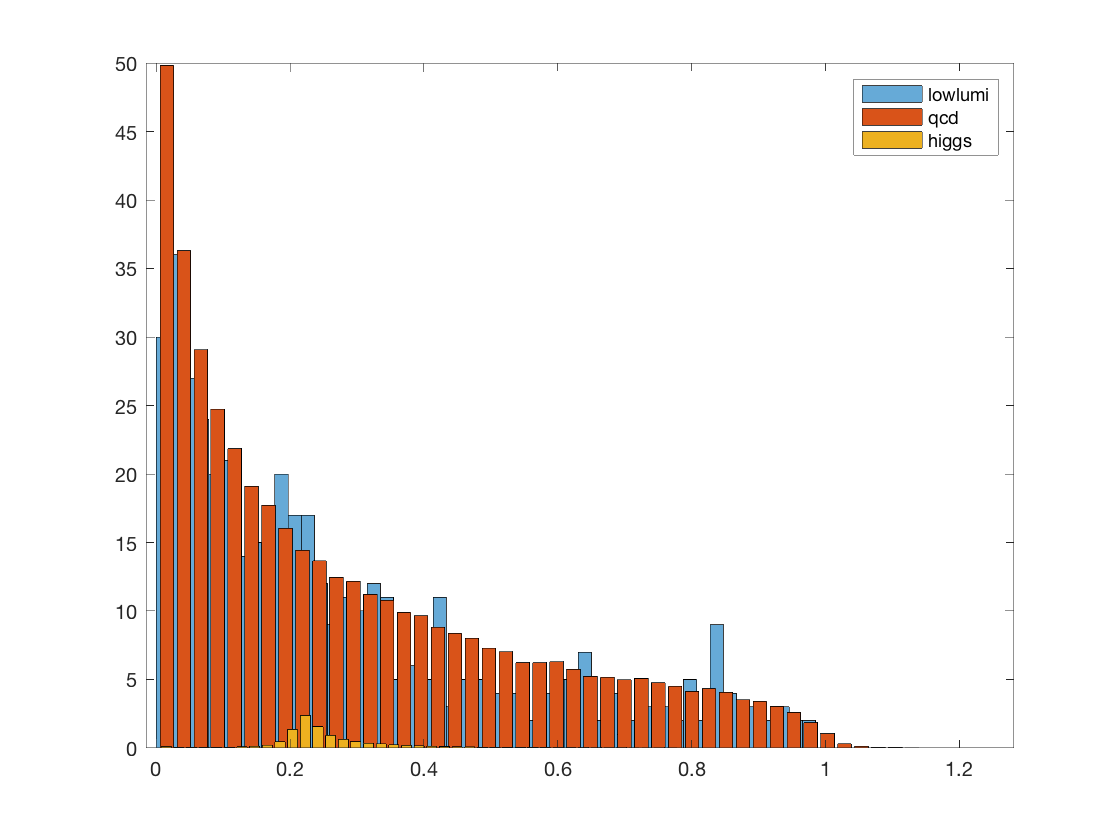


ktdR_qcd = qcd(14,:);
ktdR_higgs = higgs(14,:);
ktdR_lowlumi = lowlumi(14,:);
l = length(lowlumi(1,:));
[C_higgs, Cen_higgs] = hist(ktdR_higgs,50);
[C_qcd, Cen_qcd] = hist(ktdR_qcd,50);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;
r_original = sum(C_higgs)/sqrt(sum(C_qcd));
histogram(lowlumi(14,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('lowlumi','qcd','higgs')
hold off

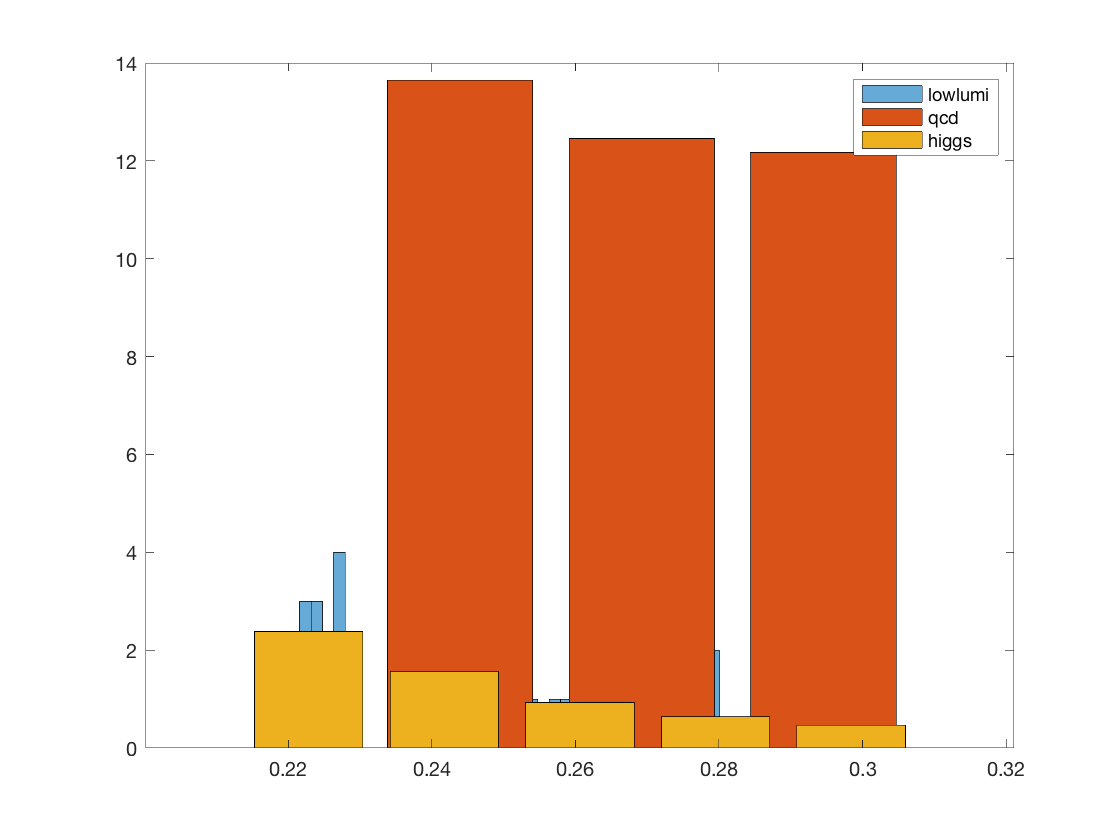


cut = 1:1:100;
cut = flip(cut);
cut = cut./100;
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(ktdR_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(ktdR_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(ktdR_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(ktdR_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(ktdR_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end
r_opti = sum(C_higgs)/sqrt(sum(C_qcd));
Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

ktdR_lowlumi(ktdR_lowlumi<cent-cut_opti(1)) = [];
ktdR_lowlumi(ktdR_lowlumi>cent+cut_opti(1)) = [];

histogram(ktdR_lowlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('lowlumi','qcd','higgs')
hold off

The ratio  $\frac{N_{\textrm{higgs}} }{N_{\textrm{qcd}} }$ (significance) before the event selection was 0.5191.

The significance after event selection was 0.9287.

In this section. I am going to do the cuts on high luminosity data and see how the significance will change.

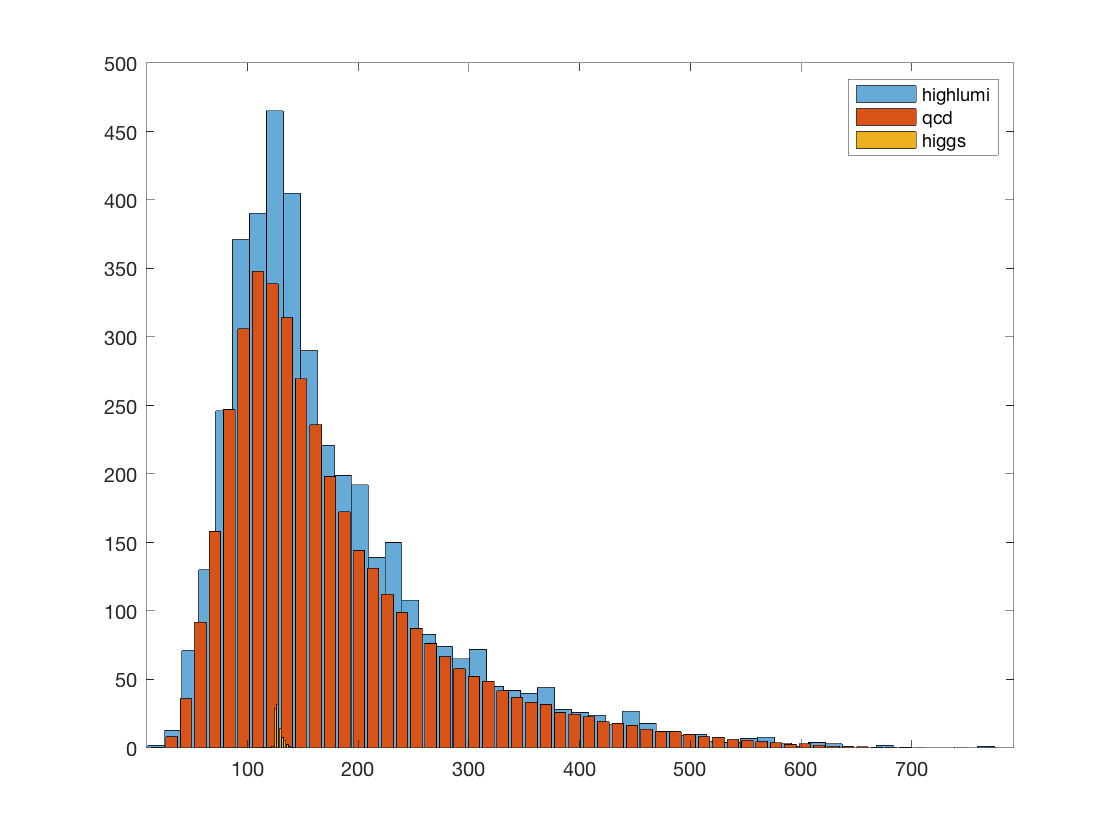


mass_qcd = qcd(4,:);
mass_higgs = higgs(4,:);
mass_highlumi = highlumi(4,:);
l = length(highlumi(1,:));
[C_higgs, Cen_higgs] = hist(mass_higgs,60);
[C_qcd, Cen_qcd] = hist(mass_qcd,60);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;

histogram(highlumi(4,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('highlumi','qcd','higgs')
hold off

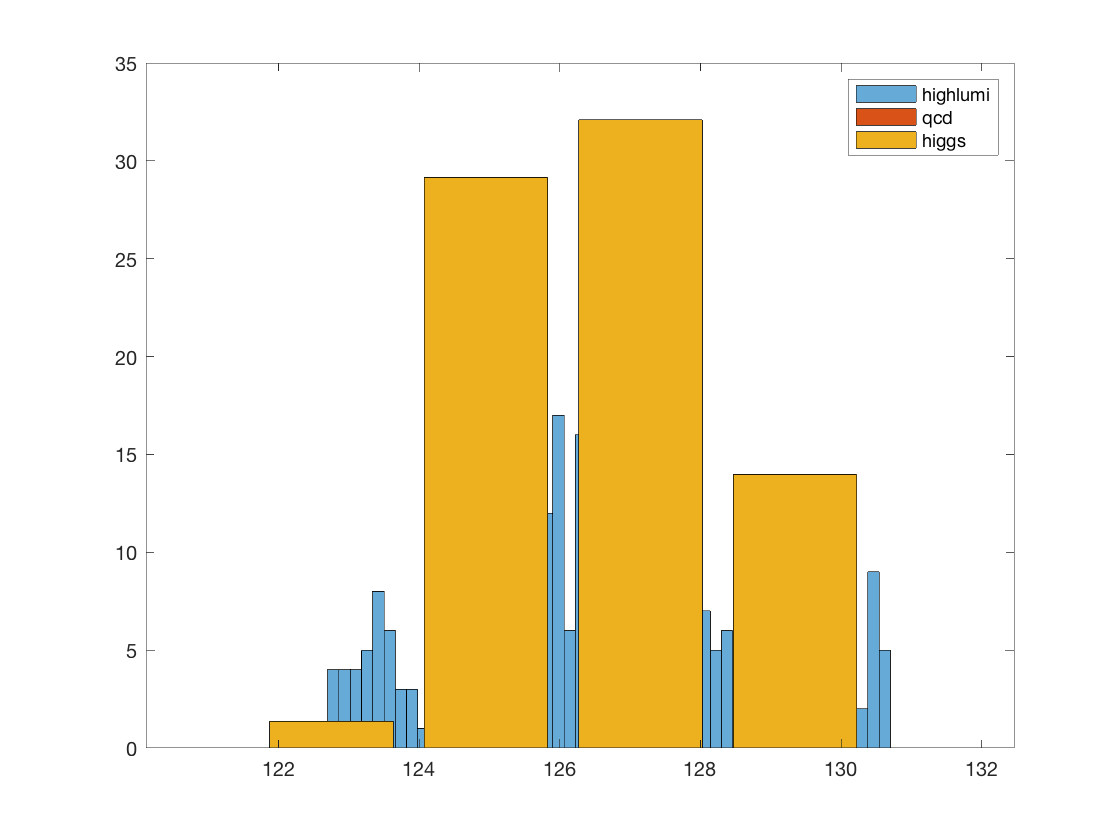


cut = 1:1:100;
cut = flip(cut);
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(mass_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(mass_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(mass_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(mass_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(mass_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end

Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

mass_highlumi(mass_highlumi<cent-cut_opti(1)) = [];
mass_highlumi(mass_highlumi>cent+cut_opti(1)) = [];

histogram(mass_highlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('highlumi','qcd','higgs')
hold off

Same as the low luminosity data. The QCD data of the mass feature in the high luminosity data were all removed.

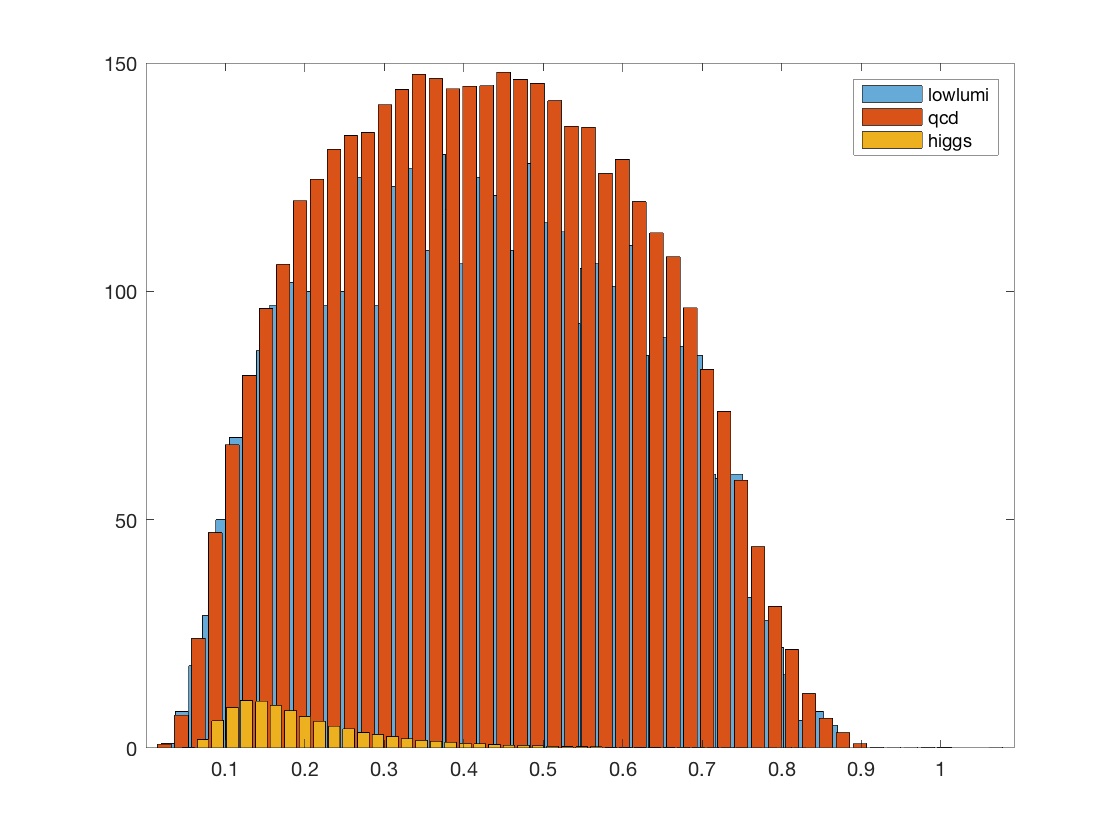


t3_qcd = qcd(11,:);
t3_higgs = higgs(11,:);
t3_highlumi = highlumi(11,:);
l = length(highlumi(1,:));
[C_higgs, Cen_higgs] = hist(t3_higgs,50);
[C_qcd, Cen_qcd] = hist(t3_qcd,50);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;
r_original = sum(C_higgs)/sqrt(sum(C_qcd));
histogram(highlumi(11,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('lowlumi','qcd','higgs')
hold off

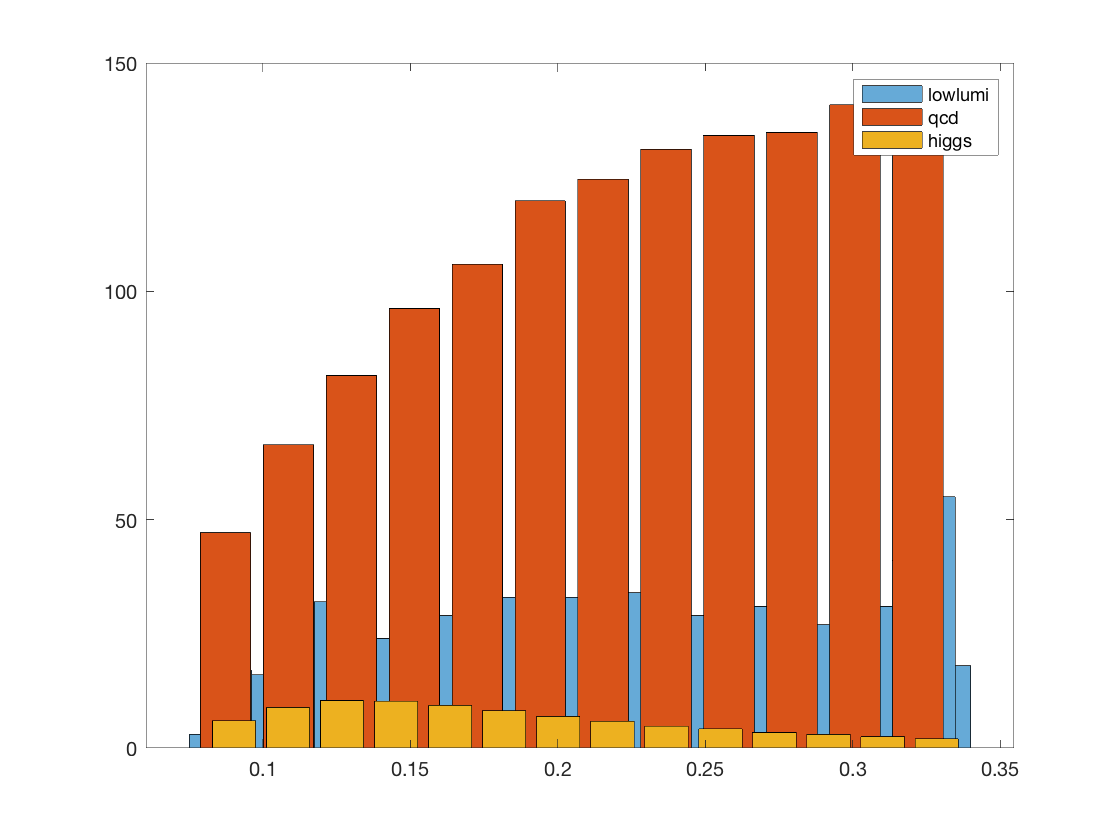


cut = 1:1:100;
cut = flip(cut);
cut = cut./100;
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(t3_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(t3_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(t3_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(t3_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(t3_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end
r_opti = sum(C_higgs)/sqrt(sum(C_qcd));
Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

t3_highlumi(t3_highlumi<cent-cut_opti(1)) = [];
t3_highlumi(t3_highlumi>cent+cut_opti(1)) = [];

histogram(t3_highlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('lowlumi','qcd','higgs')
hold off

The expected significance of the data before cuts is 1.5746.

The expected significance of the data after cuts is 2.3535.

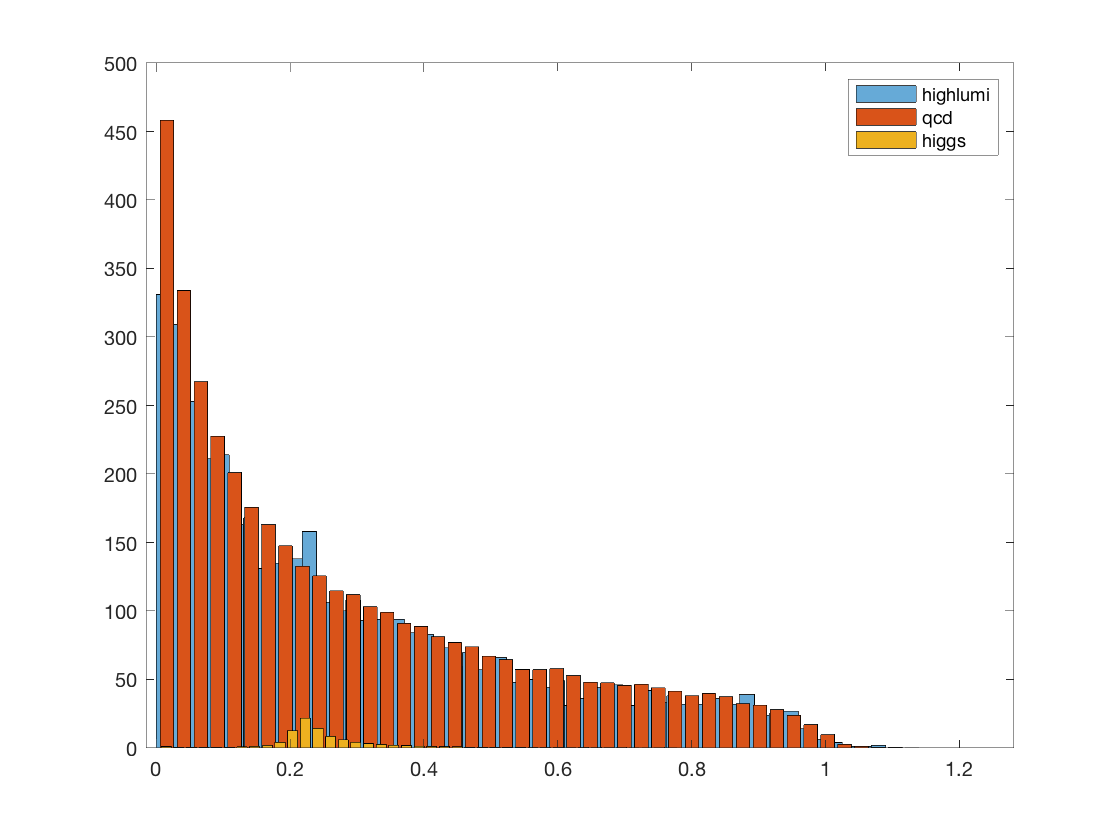


ktdR_qcd = qcd(14,:);
ktdR_higgs = higgs(14,:);
ktdR_highlumi = highlumi(14,:);
l = length(highlumi(1,:));
[C_higgs, Cen_higgs] = hist(ktdR_higgs,50);
[C_qcd, Cen_qcd] = hist(ktdR_qcd,50);

C_higgs = C_higgs./sum(C_higgs).*l.*50/2050;
C_qcd = C_qcd./sum(C_qcd).*l.*2000/2050;
r_original = sum(C_higgs)/sqrt(sum(C_qcd));
histogram(highlumi(14,:),50);
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs)
legend('highlumi','qcd','higgs')
hold off

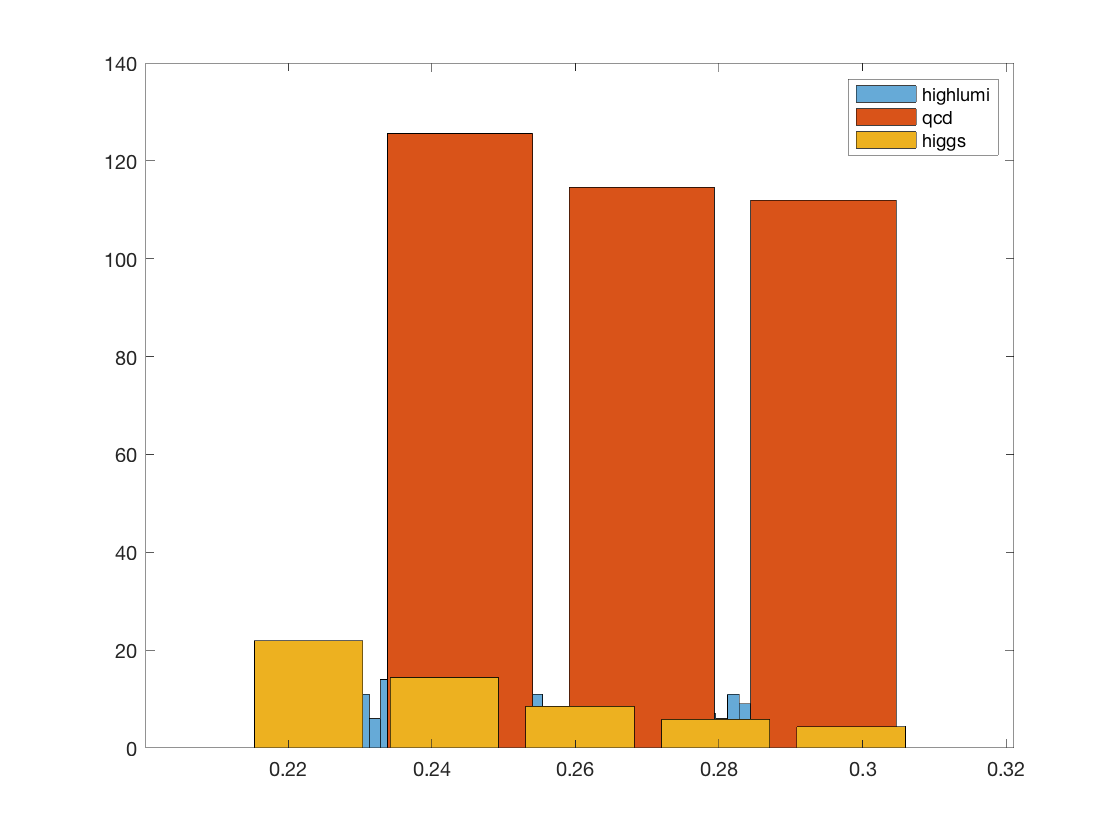


cut = 1:1:100;
cut = flip(cut);
cut = cut./100;
for i = 1:100
    
    i_higgs_r = Cen_higgs>=mean(ktdR_higgs)+cut(i);
    i_higgs_l = Cen_higgs<=mean(ktdR_higgs)-cut(i);
    i_qcd_r = Cen_qcd>=mean(ktdR_higgs)+cut(i);
    i_qcd_l = Cen_qcd<=mean(ktdR_higgs)-cut(i);
    
    N_higgs = sum(C_higgs)-sum(C_higgs(i_higgs_l))-...
        sum(C_higgs(i_higgs_r));
    N_qcd = sum(C_qcd)-sum(C_qcd(i_qcd_l))-...
        sum(C_qcd(i_qcd_r));
    ratio(i) = N_higgs/sqrt(N_qcd);
end
index = ratio==max(ratio);
cut_opti = cut(index);
cent = mean(ktdR_higgs);

remove1 = C_higgs(Cen_higgs<cent-cut_opti(1));
remove2 = C_higgs(Cen_higgs>cent+cut_opti(1));
for i = 1:length(remove1)
    C_higgs(C_higgs==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_higgs(C_higgs==remove2(i)) = [];
end

remove1 = C_qcd(Cen_qcd<cent-cut_opti(1));
remove2 = C_qcd(Cen_qcd>cent+cut_opti(1));
for i = 1:length(remove1)
    C_qcd(C_qcd==remove1(i)) = [];
end
for i = 1:length(remove2)
    C_qcd(C_qcd==remove2(i)) = [];
end
r_opti = sum(C_higgs)/sqrt(sum(C_qcd));
Cen_higgs(Cen_higgs<cent-cut_opti(1)) = [];
Cen_higgs(Cen_higgs>cent+cut_opti(1)) = [];
Cen_qcd(Cen_qcd<cent-cut_opti(1)) = [];
Cen_qcd(Cen_qcd>cent+cut_opti(1)) = [];

ktdR_highlumi(ktdR_highlumi<cent-cut_opti(1)) = [];
ktdR_highlumi(ktdR_highlumi>cent+cut_opti(1)) = [];

histogram(ktdR_highlumi,50)
hold on
bar(Cen_qcd,C_qcd);
bar(Cen_higgs,C_higgs);
legend('highlumi','qcd','higgs')
hold off

The expected significance of the data before cuts is 1.5746.

The expected significance of the data after cuts is 2.9336.

## Calculate 95% confidence interval

In the set of low luminosity data, signals have a significance that is lower than 5 sigma. I am going to calculate the upper and lower bound of the 95% confidence interval.

The measurement of a constant signal usually have some uncertainties. It means that measuring a signal with constant strength may yields a range of reading on the detectors. To calculate the upper and lower bound of the 95% confidence interval is basically answering the folloing question:

If we observe a candidate signal X. The probability of the true signal being greater than X is 95%. (X is the lower bound of 95% interval)

If we observe a candidate signal X. The probability of the true signal being smaller than X is 95%. (X is the upper bound of 95% interval)

The following code will calculate the 95% interval of mass, t3, and ktdeltaR features.

Finding 95% upper and lower bound for mass feature:


l = length(lowlumi(1,:));
[C_higgs_m, Cen_higgs_m] = hist(mass_higgs,60);
C_higgs_m = C_higgs_m./sum(C_higgs_m).*l.*50/2050;
C_higgs_m = C_higgs_m./sum(C_higgs_m);
for i = 1:length(C_higgs_m)
    P1 = sum(C_higgs_m(1:i));
    if P1>=0.05
        i_lb = i;
        break
    end    
    
end
lb_m = Cen_higgs_m(i_lb)

lb_m = 122.7526


for i = 1:length(C_higgs_m)
    P2 = sum(C_higgs_m(1:i));
    if P2>=0.95
        i_ub = i;
        break
    end    
    
end
ub_m = Cen_higgs_m(i_ub)

ub_m = 133.7392

The lower bound and upper bound of 95% confidence interval for mass feature is : [122.7526, 133.7392]

Finding 95% upper and lower bound for t3 feature:


l = length(lowlumi(1,:));
[C_higgs_t3, Cen_higgs_t3] = hist(t3_higgs,60);
C_higgs_t3 = C_higgs_t3./sum(C_higgs_t3).*l.*50/2050;
C_higgs_t3 = C_higgs_t3./sum(C_higgs_t3);
for i = 1:length(C_higgs_t3)
    P1 = sum(C_higgs_t3(1:i));
    if P1>=0.05
        i_lb = i;
        break
    end    
    
end
lb_t3 = Cen_higgs_t3(i_lb)

lb_t3 = 0.0978


for i = 1:length(C_higgs_t3)
    P2 = sum(C_higgs_t3(1:i));
    if P2>=0.95
        i_ub = i;
        break
    end    
    
end
ub_t3 = Cen_higgs_t3(i_ub)

ub_t3 = 0.4338

The lower bound and upper bound of 95% confidence interval for t3 feature is : [0.0978, 0.4338]

Finding 95% upper and lower bound for ktdeltaR feature:


l = length(lowlumi(1,:));
[C_higgs_ktdR, Cen_higgs_ktdR] = hist(ktdR_higgs,60);
C_higgs_ktdR = C_higgs_ktdR./sum(C_higgs_ktdR).*l.*50/2050;
C_higgs_ktdR = C_higgs_ktdR./sum(C_higgs_ktdR);
for i = 1:length(C_higgs_ktdR)
    P1 = sum(C_higgs_ktdR(1:i));
    if P1>=0.05
        i_lb = i;
        break
    end    
    
end
lb_ktdR = Cen_higgs_ktdR(i_lb)

lb_ktdR = 0.1394


for i = 1:length(C_higgs_ktdR)
    P2 = sum(C_higgs_ktdR(1:i));
    if P2>=0.95
        i_ub = i;
        break
    end    
    
end
ub_ktdR = Cen_higgs_t3(i_ub)

ub_ktdR = 0.4796

The lower bound and upper bound of 95% confidence interval for ktdeltaR feature is : [0.1394, 0.4796]